root_dir = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization"

root_dir = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization"

data_root_dir = root_dir + "/data/crcns-pvc1/crcns-ringach-data/";
neuro_root_dir = "neurodata/ac1/";
movie_root_dir = "movie_frames/movie000_000.images/";
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

load_img = strcat(data_root_dir, movie_root_dir, current_movie);

%if ~strcmp(str1, str2)
%    disp('Strings are different');
%end

imread(load_img);

## Total Number of Conditions

pepANA.no_conditions

## Arrival Times for electrodes in pepANA.elec_list

pepANA.listOfResults{1}.repeat{1}.data{13}

ans = 1×2 cell array
    {[0.3537 0.4543 0.6036 0.6780 1.0123 1.1758 1.1779 1.1914 1.4126 1.4425 1.5338 1.6866 1.9662 2.5828 2.9451 3.3012 3.7744 3.9322 4.0201 4.6491 4.6791 4.7038 4.7153 4.7283 4.7530 4.9453 5.0114 5.0702 5.1571 5.2284 5.2450 5.2530 5.2793 5.3124 5.4489 5.4555 5.5446 5.6120 5.6444 5.9074 5.9447 6.0529 6.1861 6.4447 6.4658 6.4674 6.5947 6.6364 6.7368 6.7395 6.7992 7.1861 7.2076 7.2251 7.4116 7.4175 7.4342 7.4409 7.7366 7.7383 7.7427 7.7602 7.7752 7.9908 7.9988 8.0911 8.1284 8.2868 8.2950 8.3093 8.6980 8.7073 8.7739 8.9820 8.9861 9.3858 9.4068 9.4084 9.4132 9.4214 9.4284 9.4361 9.4736 9.4948 11.3779 11.5023 11.5521 11.5728 12.3103 12.4606 12.6606 12.7947 12.7983 12.9645 13.7019 13.7352 13.8687 14.5684 14.5775 14.6017 14.6351 14.6436 14.8638 14.8761 15.2851 15.3940 15.4686 15.4931 15.7483 16.3330 16.3440 16.8394 17.2726 17.2844 17.3010 17.4568 17.4682 17.5766 17.7683 18.4053 18.7387 19.0184 19.0555 19.1096 19.2100 19.6099 19.8890 19.8935 19.9430 19.9933 20.5885 22.0093 2

## Detected Waveforms at that time (48 samples of waveform snippets) (contains spikes and noise bc of low threshold) (1.6ms sampled at 30kHz at int8 precision)

pepANA.listOfResults{1}.repeat{1}.data{1}{2}

ans = 48×573 int8 matrix
     0    -6    -2     3    -3    -8     3     0    10    -7    -2     4    -6     3    -5     8    -8    -8    -3   -11     4   -15    -3    -8     9     2    -6    -4    -8    -1    -7     0    -9    10    -6     5    -7    -9    16    -3    20    -1   -11     9     0    -9    -3     5    -5   -16
    -1    -3    -2     2    -1     1    -3    -3    -2    -4    -3     7    -7     1    -7     5    -3    -9     1    -5     2   -18    -6   -16    -2     5   -10    -1    -7     3   -10    -1    -9     0     0     7   -13   -10     4    -7    17    -3   -17    -2     4   -14    -9     9    -8   -19
     3    -3    -2     1    -1     8    -3    -5    -8    -2     4     6    -6    -5    -7     2    -4     0     2    -1     1   -13    -4   -14    -7     4   -12    -8     1     3    -6    -5    -7    -7     2     5   -14    -5     3     5    18     2   -12    -7     7    -7   -12     4    -7   -11
     1    -3    -3     1    -3     6     1    -6    -2    -3     1     3

pepANA.listOfResults{1}.repeat{1}.data{1}{1}

ans =     0.4543    0.5465    0.8413    0.8919    1.0303    1.0468    1.0921    1.0955    1.0975    1.1127    1.1340    1.1364    1.1461    1.1505    1.1536    1.1659    1.1676    1.1728    1.1845    1.1907    1.1957    1.2081    1.2114    1.2207    1.2462    1.3205    1.7505    1.7624    2.0124    2.0194    2.6703    2.8907    2.9705    3.1544    3.2081    3.2501    3.8376    3.8666    3.8696    3.8726    3.8750    3.8808    3.8824    3.8884    3.8904    3.8929    3.8959    3.9338    3.9362    3.9381


% Length of each sample in ms
(size(pepANA.listOfResults{1}.repeat{1}.data{1}{2}', 2) / 30000) * 1000

ans = 1.6000

pepANA.listOfResults{1}.repeat{1}.data{1}{2}'

ans = 573×48 int8 matrix
     0    -1     3     1     1     2     0    -9   -19   -24   -16   -11   -17   -14    -9     1    -3    -7     0     2    -1    -3     0     9     9     5     4     1    -6    -7    -4    -3    -8    -9     1     0    -5     0     3     1     3     8     5     4     7    13    15     7
    -6    -3    -3    -3    -4    -8   -14   -15   -19   -26   -14    -4    -2    -1    -2    -3    -2    -3    -7    -9    -7    -4    -2     2     0    -1    -8    -6     3     5     8     6     9     7     1    -7    -6     1    -2    -3     1     4     0    -5    -2     3     1    -5
    -2    -2    -2    -3    -2    -1    -1   -12   -22   -23   -14     1    -3    -7    -8   -12   -14   -12    -6     2    -4    -7   -10    -6    -4     1     3     8     1     0     4    -2     1     5     5     3    -1    -4    -5     3     0    -4    -6    -9   -12    -6    -3    -3
     3     2     1     1     2     3    -6   -12   -16   -23   -18   -13   -11    -7     0     0     1     3

pepANA.listOfResults{1}.repeat{1}.data{1}{1}

ans =     0.4543    0.5465    0.8413    0.8919    1.0303    1.0468    1.0921    1.0955    1.0975    1.1127    1.1340    1.1364    1.1461    1.1505    1.1536    1.1659    1.1676    1.1728    1.1845    1.1907    1.1957    1.2081    1.2114    1.2207    1.2462    1.3205    1.7505    1.7624    2.0124    2.0194    2.6703    2.8907    2.9705    3.1544    3.2081    3.2501    3.8376    3.8666    3.8696    3.8726    3.8750    3.8808    3.8824    3.8884    3.8904    3.8929    3.8959    3.9338    3.9362    3.9381


## Electrodes

pepANA.elec_list

ans =      5     6    10    13    15    22    23    26    38    46    47    54    55    73    78    85


## Examining Waveforms

q = pepANA.listOfResults{1}.repeat{1}.data{1}{2}

q = 48×573 int8 matrix
     0    -6    -2     3    -3    -8     3     0    10    -7    -2     4    -6     3    -5     8    -8    -8    -3   -11     4   -15    -3    -8     9     2    -6    -4    -8    -1    -7     0    -9    10    -6     5    -7    -9    16    -3    20    -1   -11     9     0    -9    -3     5    -5   -16
    -1    -3    -2     2    -1     1    -3    -3    -2    -4    -3     7    -7     1    -7     5    -3    -9     1    -5     2   -18    -6   -16    -2     5   -10    -1    -7     3   -10    -1    -9     0     0     7   -13   -10     4    -7    17    -3   -17    -2     4   -14    -9     9    -8   -19
     3    -3    -2     1    -1     8    -3    -5    -8    -2     4     6    -6    -5    -7     2    -4     0     2    -1     1   -13    -4   -14    -7     4   -12    -8     1     3    -6    -5    -7    -7     2     5   -14    -5     3     5    18     2   -12    -7     7    -7   -12     4    -7   -11
     1    -3    -3     1    -3     6     1    -6    -2    -3     1     3  


% size(q(1, :))
% one_waveform = q(1, 48);

size(q(:, :));

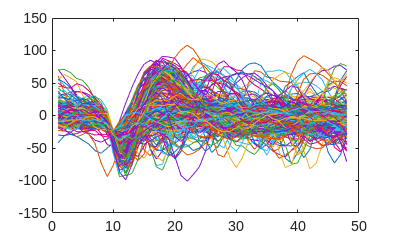

fig0 = figure("Name", "Waveform");
ax_0 = axes("Parent", fig0);
h = plot(ax_0, q);

numel(h)

ans = 573

% fig_multiple_spikes_electrode13 = figure("Name", "Channel 13 Electrode");
% ax_multi_spikes_channel13 = axes("Parent", fig_multiple_spikes_electrode13);
% plot(ax_multi_spikes_channel13, q);

## SVD of Waveforms

function filtered_signal_idxs = analyzeWaveform(condition, electrode, verbose)
    if nargin < 3
        verbose = false;
    end    

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveforms
    waveforms = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

    % Ensure waveforms are in double precision
    waveforms = double(waveforms);

    % Perform SVD
    [~, ~, v] = svd(waveforms);

    % Plot first two principal components
    if verbose
        fig1 = figure('Name', 'Original Waveforms', 'Position', [100, 100, 800, 600]);
        ax1 = axes('Parent', fig1);
        plot(ax1, v(:, 1), v(:, 2), '.', 'MarkerSize', 10);
        hold(ax1, 'on');
        plot(ax1, 0, 0, 'r.', 'MarkerSize', 25);
        xlabel(ax1, '1st Principal Component');
        ylabel(ax1, '2nd Principal Component');
        title(ax1, sprintf('SVD Projection: Condition %d, Electrode %d', condition, electrode));
        grid(ax1, 'on');
    end
        

    idx = kmeans(double(waveforms'),2); %% cluster waveforms in 2 classes using k-means
    idx1 = find(idx==1); 
    idx2 = find(idx==2);

    % Determine which cluster is likely the signal
    mean1 = mean(waveforms(:, idx1), 2);
    mean2 = mean(waveforms(:, idx2), 2);

    total_amplitude1 = sum(abs(mean1));
    total_amplitude2 = sum(abs(mean2));

    if total_amplitude1 > total_amplitude2
        signal_idx = idx1;
        noise_idx = idx2;
    else
        signal_idx = idx2;
        noise_idx = idx1;
    end

    if verbose
        fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
        ax3_1 = subplot(1, 2, 1, "Parent", fig2);
        plot(ax3_1, v(noise_idx, 1), v(noise_idx, 2), 'b.', 'markersize',10); 
        hold on;
        plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
        plot(ax3_1, v(signal_idx, 1), v(signal_idx, 2), 'g.', 'markersize', 10);
    
        ax3_2 = subplot(1, 2, 2, "Parent", fig2);
        errorbar(ax3_2, 1:size(waveforms,1), mean(double(waveforms(:, signal_idx)'),1), std(double(waveforms(:, signal_idx)'),[],1), 'g'); 
        hold on;
        errorbar(ax3_2, 1:size(waveforms,1), mean(double(waveforms(:, noise_idx)'),1), std(double(waveforms(:, noise_idx)'),[],1), 'b');
    
        xlim([0 49])
    end

    filtered_signal_idxs = signal_idx;
    % mean_detected_signal = mean(double(waveforms(:, signal_idx)'),1);
end

data_root_dir = root_dir + "/data/crcns-pvc1/crcns-ringach-data/";
neuro_root_dir = "neurodata/ac1/";
movie_root_dir = "movie_frames/movie000_000.images/";
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

% Verifying the time between the samples varies
% time_stamp = pepANA.listOfResults{1}.repeat{1}.data{1}
% time_stamp{1}(1) - time_stamp{1}(2)
% time_stamp{1}(2) - time_stamp{1}(3)

## Collecting all filtered data for machine learning purposes

% condition = 1
% electrode = 1
% signal = analyzeWaveform(condition, electrode, true);
% 
% % Plotting the detected spike waveform only
% fig0 = figure('Name', 'Detected Waveform', 'Position', [100, 100, 800, 600]);
% ax0 = axes('Parent', fig0);
% plot(ax0, signal)

function signal = extract_waveform(condition, electrode, filtered_signal_idx)

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveforms
    waveforms = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

    % Ensure waveforms are in double precision
    waveforms = double(waveforms);

    signal = double(waveforms(:, filtered_signal_idx));
end


function time = extract_waveform_timestamp(condition, electrode, filtered_signal_idx)

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveforms
    times = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{1};

    time = times(1, filtered_signal_idx);
end

function stimulus_image = identify_stimulus_image(condition, electrode, filtered_signal_idx, latency, verbose)

    if nargin < 5
        verbose = false;
    end

    if nargin < 4
        latency = 60e-3;
        verbose = false;
    end

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    data_root_dir = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/";

    movie_id = pepANA.listOfResults{condition}.values(1);
    segment_id = pepANA.listOfResults{condition}.values(2);

    if segment_id{1} > 0
        n_prefix_zeros = 3 - (floor(log10(segment_id{1})) + 1);
        if n_prefix_zeros > 1
            prefix_zeros_segment_id = sprintf('%s', repmat("0", 1, n_prefix_zeros));
        elseif n_prefix_zeros == 0
            prefix_zeros_segment_id = "";
        else
            prefix_zeros_segment_id = "0";
        end
    else
        prefix_zeros_segment_id = "00";
    end

    % Indices of the movie frame that appeared 60ms before a spike 
    % c = 1 % condition
    T = 3/90; % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
    % electrode = 1
    spk = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{1};
    spk = spk - latency; % frames of latency value (default is 60 ms) before a spike sample
    spk(spk < 0) = 0;
    frame_idxs = floor(spk/T);
    frame_idx = frame_idxs(filtered_signal_idx);
    % Create the string to show the image that is the stimulus to the detected spike
    if verbose
        sprintf('frame: %d', frame_idx)
    end
    if frame_idx > 0
        n_prefix_frame_zeros = 3 - (floor(log10(frame_idx)) + 1);
        if n_prefix_frame_zeros > 1
            prefix_zeros_frame_idx = sprintf('%s', repmat("0", 1, n_prefix_frame_zeros));
        elseif n_prefix_frame_zeros == 0
            prefix_zeros_frame_idx = "";
        else
            prefix_zeros_frame_idx = "0";
        end
    else 
        prefix_zeros_frame_idx = "00";
    end

    movie_image_string = "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + "_" + prefix_zeros_frame_idx + int2str(frame_idx) + ".jpeg";
    movie_image_dir = data_root_dir + "movie_frames/" + "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + ".images/";

    if verbose
        sprintf('movie_image_string: %s', movie_image_string)
    end

    image_path = strcat(movie_image_dir, movie_image_string);
    stimulus_image = imread(image_path);

    if verbose
        fig_img = figure("Name", "Stimulus Image");
        ax_img = axes("Parent", fig_img);
        imshow(stimulus_image,"Parent", ax_img)
    end
end


## Creating and saving 120 batches of electrode data (1 per condition)

for condition = 1:1
    All_Filtered_Data = struct('condition_id', {}, "electrodes", {});
    filtered_signals = struct('electrode', {}, "data", {});
    signal_data = struct("waveform", {}, "signal_waveform_timestamp", {}, "stimulus_image", {}, "latency_from_image_to_signal_waveform_timestamp", {}, "filtered_signal_frame_idx", {});
    latency = 60e-3; % defaulting to 60 ms between signal response and image stimulus
    for electrode = 1:16
        filtered_signal_idxs = analyzeWaveform(condition, electrode, false);
        for idx = 1:length(filtered_signal_idxs)
            signal_data(idx).waveform = extract_waveform(condition, electrode, idx);
            signal_data(idx).signal_waveform_timestamp = extract_waveform_timestamp(condition, electrode, idx);
            signal_data(idx).stimulus_image = identify_stimulus_image(condition, electrode, idx, latency, false);
            signal_data(idx).latency_from_image_to_signal_waveform_timestamp = latency;
            signal_data(idx).filtered_signal_frame_idx = filtered_signal_idxs(idx);
        end
        filtered_signals(electrode).electrode = electrode;
        filtered_signals(electrode).data = signal_data;
    end
    All_Filtered_Data(condition).condition_id = condition;
    All_Filtered_Data(condition).electrodes = filtered_signals;

    % Assumptions:
    % - `All_Filtered_Data` exists in the workspace
    % - You're working with a specific condition and electrode
    % - You want to save everything except the raw image to a CSV
    
    % Define the condition and electrode index you're working with
    condition_idx = condition;
    electrode_idx = electrode;
    
    % Extract the list of signal data entries
    entries = All_Filtered_Data(condition_idx).electrodes(electrode_idx).data;
    
    % Preallocate cell array for the table
    n_entries = numel(entries);
    waveform_lengths = numel(entries(1).waveform);
    T = table();
    
    for i = 1:n_entries
        entry = entries(i);
    
        % Convert waveform to a row vector
        waveform_row = reshape(entry.waveform, 1, []);
    
        % Create a row for the table
        new_row = table( ...
            {waveform_row}, ...
            entry.signal_waveform_timestamp, ...
            entry.latency_from_image_to_signal_waveform_timestamp, ...
            entry.filtered_signal_frame_idx, ...
            'VariableNames', { ...
                'waveform', ...
                'signal_waveform_timestamp', ...
                'latency_from_image_to_signal_waveform_timestamp', ...
                'filtered_signal_frame_idx' ...
            } ...
        );
    
        % Append to table
        T = [T; new_row];
    end
    
    save_filename = sprintf("filtered_signal_data_condition_%d_electrode_%d.csv", condition_idx, electrode_idx)
    % Save to CSV file (waveform saved as string for now)
    
    file_write_path = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization/data/filtered_signal_data/signal_csv/" + save_filename
    writetable(T, file_write_path)
    
    % Extracting the image
    % Set output folder
    output_folder = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization/data/filtered_signal_data/stimulus_images/";
    
    
    % Loop through each condition
    for condition_number = condition_idx
        
        electrodes = All_Filtered_Data(condition_number).electrodes;
        
        % Loop through each electrode
        for electrode_number = 1:length(electrodes)
            
            signal_data = electrodes(electrode_number).data;
            
            % Loop through each entry in signal_data
            for i = 1:length(signal_data)
                
                % Extract image
                img = signal_data(i).stimulus_image;
                
                % Generate filename
                filename = sprintf('condition_%02d_electrode_%02d_sample_%03d.png', ...
                                    condition_number, electrode_number, i)
                
                % Full path
                filepath = fullfile(output_folder, filename);
                
                % Save image
                imwrite(img, filepath)
            end
        end
    end
    
    clear All_Filtered_Data;
end

save_filename = "filtered_signal_data_condition_1_electrode_16.csv"

file_write_path = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization/data/filtered_signal_data/signal_csv/filtered_signal_data_condition_1_electrode_16.csv"

filename = 'condition_01_electrode_01_sample_001.png'

filename = 'condition_01_electrode_01_sample_002.png'

filename = 'condition_01_electrode_01_sample_003.png'

filename = 'condition_01_electrode_01_sample_004.png'

filename = 'condition_01_electrode_01_sample_005.png'

filename = 'condition_01_electrode_01_sample_006.png'

filename = 'condition_01_electrode_01_sample_007.png'

filename = 'condition_01_electrode_01_sample_008.png'

filename = 'condition_01_electrode_01_sample_009.png'

filename = 'condition_01_electrode_01_sample_010.png'

filename = 'condition_01_electrode_01_sample_011.png'

filename = 'condition_01_electrode_01_sample_012.png'

filename = 'condition_01_electrode_01_sample_013.png'

filename = 'condition_01_electrode_01_sample_014.png'

filename = 'condition_01_electrode_01_sample_015.png'

filename = 'condition_01_electrode_01_sample_016.png'

filename = 'condition_01_electrode_01_sample_017.png'

filename = 'condition_01_electrode_01_sample_018.png'

filename = 'condition_01_electrode_01_sample_019.png'

filename = 'condition_01_electrode_01_sample_020.png'

filename = 'condition_01_electrode_01_sample_021.png'

filename = 'condition_01_electrode_01_sample_022.png'

filename = 'condition_01_electrode_01_sample_023.png'

filename = 'condition_01_electrode_01_sample_024.png'

filename = 'condition_01_electrode_01_sample_025.png'

filename = 'condition_01_electrode_01_sample_026.png'

filename = 'condition_01_electrode_01_sample_027.png'

filename = 'condition_01_electrode_01_sample_028.png'

filename = 'condition_01_electrode_01_sample_029.png'

filename = 'condition_01_electrode_01_sample_030.png'

filename = 'condition_01_electrode_01_sample_031.png'

filename = 'condition_01_electrode_01_sample_032.png'

filename = 'condition_01_electrode_01_sample_033.png'

filename = 'condition_01_electrode_01_sample_034.png'

filename = 'condition_01_electrode_01_sample_035.png'

filename = 'condition_01_electrode_01_sample_036.png'

filename = 'condition_01_electrode_01_sample_037.png'

filename = 'condition_01_electrode_01_sample_038.png'

filename = 'condition_01_electrode_01_sample_039.png'

filename = 'condition_01_electrode_01_sample_040.png'

filename = 'condition_01_electrode_01_sample_041.png'

filename = 'condition_01_electrode_01_sample_042.png'

filename = 'condition_01_electrode_01_sample_043.png'

filename = 'condition_01_electrode_01_sample_044.png'

filename = 'condition_01_electrode_01_sample_045.png'

filename = 'condition_01_electrode_01_sample_046.png'

filename = 'condition_01_electrode_01_sample_047.png'

filename = 'condition_01_electrode_01_sample_048.png'

filename = 'condition_01_electrode_01_sample_049.png'

filename = 'condition_01_electrode_01_sample_050.png'

filename = 'condition_01_electrode_01_sample_051.png'

filename = 'condition_01_electrode_01_sample_052.png'

filename = 'condition_01_electrode_01_sample_053.png'

filename = 'condition_01_electrode_01_sample_054.png'

filename = 'condition_01_electrode_01_sample_055.png'

filename = 'condition_01_electrode_01_sample_056.png'

filename = 'condition_01_electrode_01_sample_057.png'

filename = 'condition_01_electrode_01_sample_058.png'

filename = 'condition_01_electrode_01_sample_059.png'

filename = 'condition_01_electrode_01_sample_060.png'

filename = 'condition_01_electrode_01_sample_061.png'

filename = 'condition_01_electrode_01_sample_062.png'

filename = 'condition_01_electrode_01_sample_063.png'

filename = 'condition_01_electrode_01_sample_064.png'

filename = 'condition_01_electrode_01_sample_065.png'

filename = 'condition_01_electrode_01_sample_066.png'

filename = 'condition_01_electrode_01_sample_067.png'

filename = 'condition_01_electrode_01_sample_068.png'

filename = 'condition_01_electrode_01_sample_069.png'

filename = 'condition_01_electrode_01_sample_070.png'

filename = 'condition_01_electrode_01_sample_071.png'

filename = 'condition_01_electrode_01_sample_072.png'

filename = 'condition_01_electrode_01_sample_073.png'

filename = 'condition_01_electrode_01_sample_074.png'

filename = 'condition_01_electrode_01_sample_075.png'

filename = 'condition_01_electrode_01_sample_076.png'

filename = 'condition_01_electrode_01_sample_077.png'

filename = 'condition_01_electrode_01_sample_078.png'

filename = 'condition_01_electrode_01_sample_079.png'

filename = 'condition_01_electrode_01_sample_080.png'

filename = 'condition_01_electrode_01_sample_081.png'

filename = 'condition_01_electrode_01_sample_082.png'

filename = 'condition_01_electrode_01_sample_083.png'

filename = 'condition_01_electrode_01_sample_084.png'

filename = 'condition_01_electrode_01_sample_085.png'

filename = 'condition_01_electrode_01_sample_086.png'

filename = 'condition_01_electrode_01_sample_087.png'

filename = 'condition_01_electrode_01_sample_088.png'

filename = 'condition_01_electrode_01_sample_089.png'

filename = 'condition_01_electrode_01_sample_090.png'

filename = 'condition_01_electrode_01_sample_091.png'

filename = 'condition_01_electrode_01_sample_092.png'

filename = 'condition_01_electrode_01_sample_093.png'

filename = 'condition_01_electrode_01_sample_094.png'

filename = 'condition_01_electrode_01_sample_095.png'

filename = 'condition_01_electrode_01_sample_096.png'

filename = 'condition_01_electrode_01_sample_097.png'

filename = 'condition_01_electrode_01_sample_098.png'

filename = 'condition_01_electrode_01_sample_099.png'

filename = 'condition_01_electrode_01_sample_100.png'

filename = 'condition_01_electrode_01_sample_101.png'

filename = 'condition_01_electrode_01_sample_102.png'

filename = 'condition_01_electrode_01_sample_103.png'

filename = 'condition_01_electrode_01_sample_104.png'

filename = 'condition_01_electrode_01_sample_105.png'

filename = 'condition_01_electrode_01_sample_106.png'

filename = 'condition_01_electrode_01_sample_107.png'

filename = 'condition_01_electrode_01_sample_108.png'

filename = 'condition_01_electrode_01_sample_109.png'

filename = 'condition_01_electrode_01_sample_110.png'

filename = 'condition_01_electrode_01_sample_111.png'

filename = 'condition_01_electrode_01_sample_112.png'

filename = 'condition_01_electrode_01_sample_113.png'

filename = 'condition_01_electrode_01_sample_114.png'

filename = 'condition_01_electrode_01_sample_115.png'

filename = 'condition_01_electrode_01_sample_116.png'

filename = 'condition_01_electrode_01_sample_117.png'

filename = 'condition_01_electrode_01_sample_118.png'

filename = 'condition_01_electrode_01_sample_119.png'

filename = 'condition_01_electrode_01_sample_120.png'

filename = 'condition_01_electrode_01_sample_121.png'

filename = 'condition_01_electrode_01_sample_122.png'

filename = 'condition_01_electrode_01_sample_123.png'

filename = 'condition_01_electrode_01_sample_124.png'

filename = 'condition_01_electrode_01_sample_125.png'

filename = 'condition_01_electrode_01_sample_126.png'

filename = 'condition_01_electrode_01_sample_127.png'

filename = 'condition_01_electrode_01_sample_128.png'

filename = 'condition_01_electrode_01_sample_129.png'

filename = 'condition_01_electrode_01_sample_130.png'

filename = 'condition_01_electrode_01_sample_131.png'

filename = 'condition_01_electrode_01_sample_132.png'

filename = 'condition_01_electrode_01_sample_133.png'

filename = 'condition_01_electrode_01_sample_134.png'

filename = 'condition_01_electrode_01_sample_135.png'

filename = 'condition_01_electrode_01_sample_136.png'

filename = 'condition_01_electrode_01_sample_137.png'

filename = 'condition_01_electrode_01_sample_138.png'

filename = 'condition_01_electrode_01_sample_139.png'

filename = 'condition_01_electrode_01_sample_140.png'

filename = 'condition_01_electrode_01_sample_141.png'

filename = 'condition_01_electrode_01_sample_142.png'

filename = 'condition_01_electrode_01_sample_143.png'

filename = 'condition_01_electrode_01_sample_144.png'

filename = 'condition_01_electrode_01_sample_145.png'

filename = 'condition_01_electrode_01_sample_146.png'

filename = 'condition_01_electrode_01_sample_147.png'

filename = 'condition_01_electrode_01_sample_148.png'

filename = 'condition_01_electrode_01_sample_149.png'

filename = 'condition_01_electrode_01_sample_150.png'

filename = 'condition_01_electrode_01_sample_151.png'

filename = 'condition_01_electrode_01_sample_152.png'

filename = 'condition_01_electrode_01_sample_153.png'

filename = 'condition_01_electrode_01_sample_154.png'

filename = 'condition_01_electrode_01_sample_155.png'

filename = 'condition_01_electrode_01_sample_156.png'

filename = 'condition_01_electrode_01_sample_157.png'

filename = 'condition_01_electrode_01_sample_158.png'

filename = 'condition_01_electrode_01_sample_159.png'

filename = 'condition_01_electrode_01_sample_160.png'

filename = 'condition_01_electrode_01_sample_161.png'

filename = 'condition_01_electrode_01_sample_162.png'

filename = 'condition_01_electrode_01_sample_163.png'

filename = 'condition_01_electrode_01_sample_164.png'

filename = 'condition_01_electrode_01_sample_165.png'

filename = 'condition_01_electrode_01_sample_166.png'

filename = 'condition_01_electrode_01_sample_167.png'

filename = 'condition_01_electrode_01_sample_168.png'

filename = 'condition_01_electrode_01_sample_169.png'

filename = 'condition_01_electrode_01_sample_170.png'

filename = 'condition_01_electrode_01_sample_171.png'

filename = 'condition_01_electrode_01_sample_172.png'

filename = 'condition_01_electrode_01_sample_173.png'

filename = 'condition_01_electrode_01_sample_174.png'

filename = 'condition_01_electrode_01_sample_175.png'

filename = 'condition_01_electrode_01_sample_176.png'

filename = 'condition_01_electrode_01_sample_177.png'

filename = 'condition_01_electrode_01_sample_178.png'

filename = 'condition_01_electrode_01_sample_179.png'

filename = 'condition_01_electrode_01_sample_180.png'

filename = 'condition_01_electrode_01_sample_181.png'

filename = 'condition_01_electrode_01_sample_182.png'

filename = 'condition_01_electrode_01_sample_183.png'

filename = 'condition_01_electrode_01_sample_184.png'

filename = 'condition_01_electrode_01_sample_185.png'

filename = 'condition_01_electrode_01_sample_186.png'

filename = 'condition_01_electrode_01_sample_187.png'

filename = 'condition_01_electrode_01_sample_188.png'

filename = 'condition_01_electrode_01_sample_189.png'

filename = 'condition_01_electrode_01_sample_190.png'

filename = 'condition_01_electrode_01_sample_191.png'

filename = 'condition_01_electrode_01_sample_192.png'

filename = 'condition_01_electrode_02_sample_001.png'

filename = 'condition_01_electrode_02_sample_002.png'

filename = 'condition_01_electrode_02_sample_003.png'

filename = 'condition_01_electrode_02_sample_004.png'

filename = 'condition_01_electrode_02_sample_005.png'

filename = 'condition_01_electrode_02_sample_006.png'

filename = 'condition_01_electrode_02_sample_007.png'

filename = 'condition_01_electrode_02_sample_008.png'

filename = 'condition_01_electrode_02_sample_009.png'

filename = 'condition_01_electrode_02_sample_010.png'

filename = 'condition_01_electrode_02_sample_011.png'

filename = 'condition_01_electrode_02_sample_012.png'

filename = 'condition_01_electrode_02_sample_013.png'

filename = 'condition_01_electrode_02_sample_014.png'

filename = 'condition_01_electrode_02_sample_015.png'

filename = 'condition_01_electrode_02_sample_016.png'

filename = 'condition_01_electrode_02_sample_017.png'

filename = 'condition_01_electrode_02_sample_018.png'

filename = 'condition_01_electrode_02_sample_019.png'

filename = 'condition_01_electrode_02_sample_020.png'

filename = 'condition_01_electrode_02_sample_021.png'

filename = 'condition_01_electrode_02_sample_022.png'

filename = 'condition_01_electrode_02_sample_023.png'

filename = 'condition_01_electrode_02_sample_024.png'

filename = 'condition_01_electrode_02_sample_025.png'

filename = 'condition_01_electrode_02_sample_026.png'

filename = 'condition_01_electrode_02_sample_027.png'

filename = 'condition_01_electrode_02_sample_028.png'

filename = 'condition_01_electrode_02_sample_029.png'

filename = 'condition_01_electrode_02_sample_030.png'

filename = 'condition_01_electrode_02_sample_031.png'

filename = 'condition_01_electrode_02_sample_032.png'

filename = 'condition_01_electrode_02_sample_033.png'

filename = 'condition_01_electrode_02_sample_034.png'

filename = 'condition_01_electrode_02_sample_035.png'

filename = 'condition_01_electrode_02_sample_036.png'

filename = 'condition_01_electrode_02_sample_037.png'

filename = 'condition_01_electrode_02_sample_038.png'

filename = 'condition_01_electrode_02_sample_039.png'

filename = 'condition_01_electrode_02_sample_040.png'

filename = 'condition_01_electrode_02_sample_041.png'

filename = 'condition_01_electrode_02_sample_042.png'

filename = 'condition_01_electrode_02_sample_043.png'

filename = 'condition_01_electrode_02_sample_044.png'

filename = 'condition_01_electrode_02_sample_045.png'

filename = 'condition_01_electrode_02_sample_046.png'

filename = 'condition_01_electrode_02_sample_047.png'

filename = 'condition_01_electrode_02_sample_048.png'

filename = 'condition_01_electrode_02_sample_049.png'

filename = 'condition_01_electrode_02_sample_050.png'

filename = 'condition_01_electrode_02_sample_051.png'

filename = 'condition_01_electrode_02_sample_052.png'

filename = 'condition_01_electrode_02_sample_053.png'

filename = 'condition_01_electrode_02_sample_054.png'

filename = 'condition_01_electrode_02_sample_055.png'

filename = 'condition_01_electrode_02_sample_056.png'

filename = 'condition_01_electrode_02_sample_057.png'

filename = 'condition_01_electrode_02_sample_058.png'

filename = 'condition_01_electrode_02_sample_059.png'

filename = 'condition_01_electrode_02_sample_060.png'

filename = 'condition_01_electrode_02_sample_061.png'

filename = 'condition_01_electrode_02_sample_062.png'

filename = 'condition_01_electrode_02_sample_063.png'

filename = 'condition_01_electrode_02_sample_064.png'

filename = 'condition_01_electrode_02_sample_065.png'

filename = 'condition_01_electrode_02_sample_066.png'

filename = 'condition_01_electrode_02_sample_067.png'

filename = 'condition_01_electrode_02_sample_068.png'

filename = 'condition_01_electrode_02_sample_069.png'

filename = 'condition_01_electrode_02_sample_070.png'

filename = 'condition_01_electrode_02_sample_071.png'

filename = 'condition_01_electrode_02_sample_072.png'

filename = 'condition_01_electrode_02_sample_073.png'

filename = 'condition_01_electrode_02_sample_074.png'

filename = 'condition_01_electrode_02_sample_075.png'

filename = 'condition_01_electrode_02_sample_076.png'

filename = 'condition_01_electrode_02_sample_077.png'

filename = 'condition_01_electrode_02_sample_078.png'

filename = 'condition_01_electrode_02_sample_079.png'

filename = 'condition_01_electrode_02_sample_080.png'

filename = 'condition_01_electrode_02_sample_081.png'

filename = 'condition_01_electrode_02_sample_082.png'

filename = 'condition_01_electrode_02_sample_083.png'

filename = 'condition_01_electrode_02_sample_084.png'

filename = 'condition_01_electrode_02_sample_085.png'

filename = 'condition_01_electrode_02_sample_086.png'

filename = 'condition_01_electrode_02_sample_087.png'

filename = 'condition_01_electrode_02_sample_088.png'

filename = 'condition_01_electrode_02_sample_089.png'

filename = 'condition_01_electrode_02_sample_090.png'

filename = 'condition_01_electrode_02_sample_091.png'

filename = 'condition_01_electrode_02_sample_092.png'

filename = 'condition_01_electrode_02_sample_093.png'

filename = 'condition_01_electrode_02_sample_094.png'

filename = 'condition_01_electrode_02_sample_095.png'

filename = 'condition_01_electrode_02_sample_096.png'

filename = 'condition_01_electrode_02_sample_097.png'

filename = 'condition_01_electrode_02_sample_098.png'

filename = 'condition_01_electrode_02_sample_099.png'

filename = 'condition_01_electrode_02_sample_100.png'

filename = 'condition_01_electrode_02_sample_101.png'

filename = 'condition_01_electrode_02_sample_102.png'

filename = 'condition_01_electrode_02_sample_103.png'

filename = 'condition_01_electrode_02_sample_104.png'

filename = 'condition_01_electrode_02_sample_105.png'

filename = 'condition_01_electrode_02_sample_106.png'

filename = 'condition_01_electrode_02_sample_107.png'

filename = 'condition_01_electrode_02_sample_108.png'

filename = 'condition_01_electrode_02_sample_109.png'

filename = 'condition_01_electrode_02_sample_110.png'

filename = 'condition_01_electrode_02_sample_111.png'

filename = 'condition_01_electrode_02_sample_112.png'

filename = 'condition_01_electrode_02_sample_113.png'

filename = 'condition_01_electrode_02_sample_114.png'

filename = 'condition_01_electrode_02_sample_115.png'

filename = 'condition_01_electrode_02_sample_116.png'

filename = 'condition_01_electrode_02_sample_117.png'

filename = 'condition_01_electrode_02_sample_118.png'

filename = 'condition_01_electrode_02_sample_119.png'

filename = 'condition_01_electrode_02_sample_120.png'

filename = 'condition_01_electrode_02_sample_121.png'

filename = 'condition_01_electrode_02_sample_122.png'

filename = 'condition_01_electrode_02_sample_123.png'

filename = 'condition_01_electrode_02_sample_124.png'

filename = 'condition_01_electrode_02_sample_125.png'

filename = 'condition_01_electrode_02_sample_126.png'

filename = 'condition_01_electrode_02_sample_127.png'

filename = 'condition_01_electrode_02_sample_128.png'

filename = 'condition_01_electrode_02_sample_129.png'

filename = 'condition_01_electrode_02_sample_130.png'

filename = 'condition_01_electrode_02_sample_131.png'

filename = 'condition_01_electrode_02_sample_132.png'

filename = 'condition_01_electrode_02_sample_133.png'

filename = 'condition_01_electrode_02_sample_134.png'

filename = 'condition_01_electrode_02_sample_135.png'

filename = 'condition_01_electrode_02_sample_136.png'

filename = 'condition_01_electrode_02_sample_137.png'

filename = 'condition_01_electrode_02_sample_138.png'

filename = 'condition_01_electrode_02_sample_139.png'

filename = 'condition_01_electrode_02_sample_140.png'

filename = 'condition_01_electrode_02_sample_141.png'

filename = 'condition_01_electrode_02_sample_142.png'

filename = 'condition_01_electrode_02_sample_143.png'

filename = 'condition_01_electrode_02_sample_144.png'

filename = 'condition_01_electrode_02_sample_145.png'

filename = 'condition_01_electrode_02_sample_146.png'

filename = 'condition_01_electrode_02_sample_147.png'

filename = 'condition_01_electrode_02_sample_148.png'

filename = 'condition_01_electrode_02_sample_149.png'

filename = 'condition_01_electrode_02_sample_150.png'

filename = 'condition_01_electrode_02_sample_151.png'

filename = 'condition_01_electrode_02_sample_152.png'

filename = 'condition_01_electrode_02_sample_153.png'

filename = 'condition_01_electrode_02_sample_154.png'

filename = 'condition_01_electrode_02_sample_155.png'

filename = 'condition_01_electrode_02_sample_156.png'

filename = 'condition_01_electrode_02_sample_157.png'

filename = 'condition_01_electrode_02_sample_158.png'

filename = 'condition_01_electrode_02_sample_159.png'

filename = 'condition_01_electrode_02_sample_160.png'

filename = 'condition_01_electrode_02_sample_161.png'

filename = 'condition_01_electrode_02_sample_162.png'

filename = 'condition_01_electrode_02_sample_163.png'

filename = 'condition_01_electrode_02_sample_164.png'

filename = 'condition_01_electrode_02_sample_165.png'

filename = 'condition_01_electrode_02_sample_166.png'

filename = 'condition_01_electrode_02_sample_167.png'

filename = 'condition_01_electrode_02_sample_168.png'

filename = 'condition_01_electrode_02_sample_169.png'

filename = 'condition_01_electrode_02_sample_170.png'

filename = 'condition_01_electrode_02_sample_171.png'

filename = 'condition_01_electrode_02_sample_172.png'

filename = 'condition_01_electrode_02_sample_173.png'

filename = 'condition_01_electrode_02_sample_174.png'

filename = 'condition_01_electrode_02_sample_175.png'

filename = 'condition_01_electrode_02_sample_176.png'

filename = 'condition_01_electrode_02_sample_177.png'

filename = 'condition_01_electrode_02_sample_178.png'

filename = 'condition_01_electrode_02_sample_179.png'

filename = 'condition_01_electrode_02_sample_180.png'

filename = 'condition_01_electrode_02_sample_181.png'

filename = 'condition_01_electrode_02_sample_182.png'

filename = 'condition_01_electrode_02_sample_183.png'

filename = 'condition_01_electrode_02_sample_184.png'

filename = 'condition_01_electrode_02_sample_185.png'

filename = 'condition_01_electrode_02_sample_186.png'

filename = 'condition_01_electrode_02_sample_187.png'

filename = 'condition_01_electrode_02_sample_188.png'

filename = 'condition_01_electrode_02_sample_189.png'

filename = 'condition_01_electrode_02_sample_190.png'

filename = 'condition_01_electrode_02_sample_191.png'

filename = 'condition_01_electrode_02_sample_192.png'

filename = 'condition_01_electrode_03_sample_001.png'

filename = 'condition_01_electrode_03_sample_002.png'

filename = 'condition_01_electrode_03_sample_003.png'

filename = 'condition_01_electrode_03_sample_004.png'

filename = 'condition_01_electrode_03_sample_005.png'

filename = 'condition_01_electrode_03_sample_006.png'

filename = 'condition_01_electrode_03_sample_007.png'

filename = 'condition_01_electrode_03_sample_008.png'

filename = 'condition_01_electrode_03_sample_009.png'

filename = 'condition_01_electrode_03_sample_010.png'

filename = 'condition_01_electrode_03_sample_011.png'

filename = 'condition_01_electrode_03_sample_012.png'

filename = 'condition_01_electrode_03_sample_013.png'

filename = 'condition_01_electrode_03_sample_014.png'

filename = 'condition_01_electrode_03_sample_015.png'

filename = 'condition_01_electrode_03_sample_016.png'

filename = 'condition_01_electrode_03_sample_017.png'

filename = 'condition_01_electrode_03_sample_018.png'

filename = 'condition_01_electrode_03_sample_019.png'

filename = 'condition_01_electrode_03_sample_020.png'

filename = 'condition_01_electrode_03_sample_021.png'

filename = 'condition_01_electrode_03_sample_022.png'

filename = 'condition_01_electrode_03_sample_023.png'

filename = 'condition_01_electrode_03_sample_024.png'

filename = 'condition_01_electrode_03_sample_025.png'

filename = 'condition_01_electrode_03_sample_026.png'

filename = 'condition_01_electrode_03_sample_027.png'

filename = 'condition_01_electrode_03_sample_028.png'

filename = 'condition_01_electrode_03_sample_029.png'

filename = 'condition_01_electrode_03_sample_030.png'

filename = 'condition_01_electrode_03_sample_031.png'

filename = 'condition_01_electrode_03_sample_032.png'

filename = 'condition_01_electrode_03_sample_033.png'

filename = 'condition_01_electrode_03_sample_034.png'

filename = 'condition_01_electrode_03_sample_035.png'

filename = 'condition_01_electrode_03_sample_036.png'

filename = 'condition_01_electrode_03_sample_037.png'

filename = 'condition_01_electrode_03_sample_038.png'

filename = 'condition_01_electrode_03_sample_039.png'

filename = 'condition_01_electrode_03_sample_040.png'

filename = 'condition_01_electrode_03_sample_041.png'

filename = 'condition_01_electrode_03_sample_042.png'

filename = 'condition_01_electrode_03_sample_043.png'

filename = 'condition_01_electrode_03_sample_044.png'

filename = 'condition_01_electrode_03_sample_045.png'

filename = 'condition_01_electrode_03_sample_046.png'

filename = 'condition_01_electrode_03_sample_047.png'

filename = 'condition_01_electrode_03_sample_048.png'

filename = 'condition_01_electrode_03_sample_049.png'

filename = 'condition_01_electrode_03_sample_050.png'

filename = 'condition_01_electrode_03_sample_051.png'

filename = 'condition_01_electrode_03_sample_052.png'

filename = 'condition_01_electrode_03_sample_053.png'

filename = 'condition_01_electrode_03_sample_054.png'

filename = 'condition_01_electrode_03_sample_055.png'

filename = 'condition_01_electrode_03_sample_056.png'

filename = 'condition_01_electrode_03_sample_057.png'

filename = 'condition_01_electrode_03_sample_058.png'

filename = 'condition_01_electrode_03_sample_059.png'

filename = 'condition_01_electrode_03_sample_060.png'

filename = 'condition_01_electrode_03_sample_061.png'

filename = 'condition_01_electrode_03_sample_062.png'

filename = 'condition_01_electrode_03_sample_063.png'

filename = 'condition_01_electrode_03_sample_064.png'

filename = 'condition_01_electrode_03_sample_065.png'

filename = 'condition_01_electrode_03_sample_066.png'

filename = 'condition_01_electrode_03_sample_067.png'

filename = 'condition_01_electrode_03_sample_068.png'

filename = 'condition_01_electrode_03_sample_069.png'

filename = 'condition_01_electrode_03_sample_070.png'

filename = 'condition_01_electrode_03_sample_071.png'

filename = 'condition_01_electrode_03_sample_072.png'

filename = 'condition_01_electrode_03_sample_073.png'

filename = 'condition_01_electrode_03_sample_074.png'

filename = 'condition_01_electrode_03_sample_075.png'

filename = 'condition_01_electrode_03_sample_076.png'

filename = 'condition_01_electrode_03_sample_077.png'

filename = 'condition_01_electrode_03_sample_078.png'

filename = 'condition_01_electrode_03_sample_079.png'

filename = 'condition_01_electrode_03_sample_080.png'

filename = 'condition_01_electrode_03_sample_081.png'

filename = 'condition_01_electrode_03_sample_082.png'

filename = 'condition_01_electrode_03_sample_083.png'

filename = 'condition_01_electrode_03_sample_084.png'

filename = 'condition_01_electrode_03_sample_085.png'

filename = 'condition_01_electrode_03_sample_086.png'

filename = 'condition_01_electrode_03_sample_087.png'

filename = 'condition_01_electrode_03_sample_088.png'

filename = 'condition_01_electrode_03_sample_089.png'

filename = 'condition_01_electrode_03_sample_090.png'

filename = 'condition_01_electrode_03_sample_091.png'

filename = 'condition_01_electrode_03_sample_092.png'

filename = 'condition_01_electrode_03_sample_093.png'

filename = 'condition_01_electrode_03_sample_094.png'

filename = 'condition_01_electrode_03_sample_095.png'

filename = 'condition_01_electrode_03_sample_096.png'

filename = 'condition_01_electrode_03_sample_097.png'

filename = 'condition_01_electrode_03_sample_098.png'

filename = 'condition_01_electrode_03_sample_099.png'

filename = 'condition_01_electrode_03_sample_100.png'

filename = 'condition_01_electrode_03_sample_101.png'

filename = 'condition_01_electrode_03_sample_102.png'

filename = 'condition_01_electrode_03_sample_103.png'

filename = 'condition_01_electrode_03_sample_104.png'

filename = 'condition_01_electrode_03_sample_105.png'

filename = 'condition_01_electrode_03_sample_106.png'

filename = 'condition_01_electrode_03_sample_107.png'

filename = 'condition_01_electrode_03_sample_108.png'

filename = 'condition_01_electrode_03_sample_109.png'

filename = 'condition_01_electrode_03_sample_110.png'

filename = 'condition_01_electrode_03_sample_111.png'

filename = 'condition_01_electrode_03_sample_112.png'

filename = 'condition_01_electrode_03_sample_113.png'

filename = 'condition_01_electrode_03_sample_114.png'

filename = 'condition_01_electrode_03_sample_115.png'

filename = 'condition_01_electrode_03_sample_116.png'

filename = 'condition_01_electrode_03_sample_117.png'

filename = 'condition_01_electrode_03_sample_118.png'

filename = 'condition_01_electrode_03_sample_119.png'

filename = 'condition_01_electrode_03_sample_120.png'

filename = 'condition_01_electrode_03_sample_121.png'

filename = 'condition_01_electrode_03_sample_122.png'

filename = 'condition_01_electrode_03_sample_123.png'

filename = 'condition_01_electrode_03_sample_124.png'

filename = 'condition_01_electrode_03_sample_125.png'

filename = 'condition_01_electrode_03_sample_126.png'

filename = 'condition_01_electrode_03_sample_127.png'

filename = 'condition_01_electrode_03_sample_128.png'

filename = 'condition_01_electrode_03_sample_129.png'

filename = 'condition_01_electrode_03_sample_130.png'

filename = 'condition_01_electrode_03_sample_131.png'

filename = 'condition_01_electrode_03_sample_132.png'

filename = 'condition_01_electrode_03_sample_133.png'

filename = 'condition_01_electrode_03_sample_134.png'

filename = 'condition_01_electrode_03_sample_135.png'

filename = 'condition_01_electrode_03_sample_136.png'

filename = 'condition_01_electrode_03_sample_137.png'

filename = 'condition_01_electrode_03_sample_138.png'

filename = 'condition_01_electrode_03_sample_139.png'

filename = 'condition_01_electrode_03_sample_140.png'

filename = 'condition_01_electrode_03_sample_141.png'

filename = 'condition_01_electrode_03_sample_142.png'

filename = 'condition_01_electrode_03_sample_143.png'

filename = 'condition_01_electrode_03_sample_144.png'

filename = 'condition_01_electrode_03_sample_145.png'

filename = 'condition_01_electrode_03_sample_146.png'

filename = 'condition_01_electrode_03_sample_147.png'

filename = 'condition_01_electrode_03_sample_148.png'

filename = 'condition_01_electrode_03_sample_149.png'

filename = 'condition_01_electrode_03_sample_150.png'

filename = 'condition_01_electrode_03_sample_151.png'

filename = 'condition_01_electrode_03_sample_152.png'

filename = 'condition_01_electrode_03_sample_153.png'

filename = 'condition_01_electrode_03_sample_154.png'

filename = 'condition_01_electrode_03_sample_155.png'

filename = 'condition_01_electrode_03_sample_156.png'

filename = 'condition_01_electrode_03_sample_157.png'

filename = 'condition_01_electrode_03_sample_158.png'

filename = 'condition_01_electrode_03_sample_159.png'

filename = 'condition_01_electrode_03_sample_160.png'

filename = 'condition_01_electrode_03_sample_161.png'

filename = 'condition_01_electrode_03_sample_162.png'

filename = 'condition_01_electrode_03_sample_163.png'

filename = 'condition_01_electrode_03_sample_164.png'

filename = 'condition_01_electrode_03_sample_165.png'

filename = 'condition_01_electrode_03_sample_166.png'

filename = 'condition_01_electrode_03_sample_167.png'

filename = 'condition_01_electrode_03_sample_168.png'

filename = 'condition_01_electrode_03_sample_169.png'

filename = 'condition_01_electrode_03_sample_170.png'

filename = 'condition_01_electrode_03_sample_171.png'

filename = 'condition_01_electrode_03_sample_172.png'

filename = 'condition_01_electrode_03_sample_173.png'

filename = 'condition_01_electrode_03_sample_174.png'

filename = 'condition_01_electrode_03_sample_175.png'

filename = 'condition_01_electrode_03_sample_176.png'

filename = 'condition_01_electrode_03_sample_177.png'

filename = 'condition_01_electrode_03_sample_178.png'

filename = 'condition_01_electrode_03_sample_179.png'

filename = 'condition_01_electrode_03_sample_180.png'

filename = 'condition_01_electrode_03_sample_181.png'

filename = 'condition_01_electrode_03_sample_182.png'

filename = 'condition_01_electrode_03_sample_183.png'

filename = 'condition_01_electrode_03_sample_184.png'

filename = 'condition_01_electrode_03_sample_185.png'

filename = 'condition_01_electrode_03_sample_186.png'

filename = 'condition_01_electrode_03_sample_187.png'

filename = 'condition_01_electrode_03_sample_188.png'

filename = 'condition_01_electrode_03_sample_189.png'

filename = 'condition_01_electrode_03_sample_190.png'

filename = 'condition_01_electrode_03_sample_191.png'

filename = 'condition_01_electrode_03_sample_192.png'

filename = 'condition_01_electrode_03_sample_193.png'

filename = 'condition_01_electrode_03_sample_194.png'

filename = 'condition_01_electrode_03_sample_195.png'

filename = 'condition_01_electrode_03_sample_196.png'

filename = 'condition_01_electrode_03_sample_197.png'

filename = 'condition_01_electrode_03_sample_198.png'

filename = 'condition_01_electrode_03_sample_199.png'

filename = 'condition_01_electrode_03_sample_200.png'

filename = 'condition_01_electrode_03_sample_201.png'

filename = 'condition_01_electrode_03_sample_202.png'

filename = 'condition_01_electrode_03_sample_203.png'

filename = 'condition_01_electrode_03_sample_204.png'

filename = 'condition_01_electrode_03_sample_205.png'

filename = 'condition_01_electrode_03_sample_206.png'

filename = 'condition_01_electrode_03_sample_207.png'

filename = 'condition_01_electrode_03_sample_208.png'

filename = 'condition_01_electrode_03_sample_209.png'

filename = 'condition_01_electrode_03_sample_210.png'

filename = 'condition_01_electrode_03_sample_211.png'

filename = 'condition_01_electrode_03_sample_212.png'

filename = 'condition_01_electrode_03_sample_213.png'

filename = 'condition_01_electrode_03_sample_214.png'

filename = 'condition_01_electrode_03_sample_215.png'

filename = 'condition_01_electrode_03_sample_216.png'

filename = 'condition_01_electrode_03_sample_217.png'

filename = 'condition_01_electrode_03_sample_218.png'

filename = 'condition_01_electrode_03_sample_219.png'

filename = 'condition_01_electrode_03_sample_220.png'

filename = 'condition_01_electrode_03_sample_221.png'

filename = 'condition_01_electrode_03_sample_222.png'

filename = 'condition_01_electrode_03_sample_223.png'

filename = 'condition_01_electrode_03_sample_224.png'

filename = 'condition_01_electrode_03_sample_225.png'

filename = 'condition_01_electrode_03_sample_226.png'

filename = 'condition_01_electrode_03_sample_227.png'

filename = 'condition_01_electrode_03_sample_228.png'

filename = 'condition_01_electrode_03_sample_229.png'

filename = 'condition_01_electrode_03_sample_230.png'

filename = 'condition_01_electrode_03_sample_231.png'

filename = 'condition_01_electrode_03_sample_232.png'

filename = 'condition_01_electrode_03_sample_233.png'

filename = 'condition_01_electrode_03_sample_234.png'

filename = 'condition_01_electrode_03_sample_235.png'

filename = 'condition_01_electrode_03_sample_236.png'

filename = 'condition_01_electrode_03_sample_237.png'

filename = 'condition_01_electrode_03_sample_238.png'

filename = 'condition_01_electrode_03_sample_239.png'

filename = 'condition_01_electrode_03_sample_240.png'

filename = 'condition_01_electrode_03_sample_241.png'

filename = 'condition_01_electrode_03_sample_242.png'

filename = 'condition_01_electrode_03_sample_243.png'

filename = 'condition_01_electrode_03_sample_244.png'

filename = 'condition_01_electrode_03_sample_245.png'

filename = 'condition_01_electrode_03_sample_246.png'

filename = 'condition_01_electrode_03_sample_247.png'

filename = 'condition_01_electrode_03_sample_248.png'

filename = 'condition_01_electrode_03_sample_249.png'

filename = 'condition_01_electrode_03_sample_250.png'

filename = 'condition_01_electrode_03_sample_251.png'

filename = 'condition_01_electrode_03_sample_252.png'

filename = 'condition_01_electrode_03_sample_253.png'

filename = 'condition_01_electrode_03_sample_254.png'

filename = 'condition_01_electrode_03_sample_255.png'

filename = 'condition_01_electrode_03_sample_256.png'

filename = 'condition_01_electrode_03_sample_257.png'

filename = 'condition_01_electrode_03_sample_258.png'

filename = 'condition_01_electrode_03_sample_259.png'

filename = 'condition_01_electrode_03_sample_260.png'

filename = 'condition_01_electrode_03_sample_261.png'

filename = 'condition_01_electrode_03_sample_262.png'

filename = 'condition_01_electrode_03_sample_263.png'

filename = 'condition_01_electrode_03_sample_264.png'

filename = 'condition_01_electrode_03_sample_265.png'

filename = 'condition_01_electrode_03_sample_266.png'

filename = 'condition_01_electrode_03_sample_267.png'

filename = 'condition_01_electrode_03_sample_268.png'

filename = 'condition_01_electrode_03_sample_269.png'

filename = 'condition_01_electrode_03_sample_270.png'

filename = 'condition_01_electrode_03_sample_271.png'

filename = 'condition_01_electrode_03_sample_272.png'

filename = 'condition_01_electrode_03_sample_273.png'

filename = 'condition_01_electrode_03_sample_274.png'

filename = 'condition_01_electrode_03_sample_275.png'

filename = 'condition_01_electrode_03_sample_276.png'

filename = 'condition_01_electrode_03_sample_277.png'

filename = 'condition_01_electrode_03_sample_278.png'

filename = 'condition_01_electrode_03_sample_279.png'

filename = 'condition_01_electrode_03_sample_280.png'

filename = 'condition_01_electrode_03_sample_281.png'

filename = 'condition_01_electrode_03_sample_282.png'

filename = 'condition_01_electrode_03_sample_283.png'

filename = 'condition_01_electrode_03_sample_284.png'

filename = 'condition_01_electrode_03_sample_285.png'

filename = 'condition_01_electrode_03_sample_286.png'

filename = 'condition_01_electrode_03_sample_287.png'

filename = 'condition_01_electrode_03_sample_288.png'

filename = 'condition_01_electrode_03_sample_289.png'

filename = 'condition_01_electrode_03_sample_290.png'

filename = 'condition_01_electrode_03_sample_291.png'

filename = 'condition_01_electrode_03_sample_292.png'

filename = 'condition_01_electrode_03_sample_293.png'

filename = 'condition_01_electrode_03_sample_294.png'

filename = 'condition_01_electrode_03_sample_295.png'

filename = 'condition_01_electrode_03_sample_296.png'

filename = 'condition_01_electrode_03_sample_297.png'

filename = 'condition_01_electrode_03_sample_298.png'

filename = 'condition_01_electrode_03_sample_299.png'

filename = 'condition_01_electrode_03_sample_300.png'

filename = 'condition_01_electrode_03_sample_301.png'

filename = 'condition_01_electrode_03_sample_302.png'

filename = 'condition_01_electrode_03_sample_303.png'

filename = 'condition_01_electrode_03_sample_304.png'

filename = 'condition_01_electrode_03_sample_305.png'

filename = 'condition_01_electrode_03_sample_306.png'

filename = 'condition_01_electrode_03_sample_307.png'

filename = 'condition_01_electrode_03_sample_308.png'

filename = 'condition_01_electrode_03_sample_309.png'

filename = 'condition_01_electrode_03_sample_310.png'

filename = 'condition_01_electrode_03_sample_311.png'

filename = 'condition_01_electrode_03_sample_312.png'

filename = 'condition_01_electrode_03_sample_313.png'

filename = 'condition_01_electrode_03_sample_314.png'

filename = 'condition_01_electrode_03_sample_315.png'

filename = 'condition_01_electrode_03_sample_316.png'

filename = 'condition_01_electrode_03_sample_317.png'

filename = 'condition_01_electrode_03_sample_318.png'

filename = 'condition_01_electrode_03_sample_319.png'

filename = 'condition_01_electrode_03_sample_320.png'

filename = 'condition_01_electrode_03_sample_321.png'

filename = 'condition_01_electrode_03_sample_322.png'

filename = 'condition_01_electrode_03_sample_323.png'

filename = 'condition_01_electrode_03_sample_324.png'

filename = 'condition_01_electrode_03_sample_325.png'

filename = 'condition_01_electrode_03_sample_326.png'

filename = 'condition_01_electrode_03_sample_327.png'

filename = 'condition_01_electrode_03_sample_328.png'

filename = 'condition_01_electrode_03_sample_329.png'

filename = 'condition_01_electrode_03_sample_330.png'

filename = 'condition_01_electrode_03_sample_331.png'

filename = 'condition_01_electrode_03_sample_332.png'

filename = 'condition_01_electrode_03_sample_333.png'

filename = 'condition_01_electrode_03_sample_334.png'

filename = 'condition_01_electrode_03_sample_335.png'

filename = 'condition_01_electrode_03_sample_336.png'

filename = 'condition_01_electrode_03_sample_337.png'

filename = 'condition_01_electrode_03_sample_338.png'

filename = 'condition_01_electrode_03_sample_339.png'

filename = 'condition_01_electrode_03_sample_340.png'

filename = 'condition_01_electrode_03_sample_341.png'

filename = 'condition_01_electrode_03_sample_342.png'

filename = 'condition_01_electrode_03_sample_343.png'

filename = 'condition_01_electrode_03_sample_344.png'

filename = 'condition_01_electrode_03_sample_345.png'

filename = 'condition_01_electrode_03_sample_346.png'

filename = 'condition_01_electrode_03_sample_347.png'

filename = 'condition_01_electrode_03_sample_348.png'

filename = 'condition_01_electrode_03_sample_349.png'

filename = 'condition_01_electrode_03_sample_350.png'

filename = 'condition_01_electrode_03_sample_351.png'

filename = 'condition_01_electrode_03_sample_352.png'

filename = 'condition_01_electrode_03_sample_353.png'

filename = 'condition_01_electrode_03_sample_354.png'

filename = 'condition_01_electrode_03_sample_355.png'

filename = 'condition_01_electrode_03_sample_356.png'

filename = 'condition_01_electrode_03_sample_357.png'

filename = 'condition_01_electrode_03_sample_358.png'

filename = 'condition_01_electrode_03_sample_359.png'

filename = 'condition_01_electrode_03_sample_360.png'

filename = 'condition_01_electrode_03_sample_361.png'

filename = 'condition_01_electrode_03_sample_362.png'

filename = 'condition_01_electrode_03_sample_363.png'

filename = 'condition_01_electrode_03_sample_364.png'

filename = 'condition_01_electrode_03_sample_365.png'

filename = 'condition_01_electrode_03_sample_366.png'

filename = 'condition_01_electrode_03_sample_367.png'

filename = 'condition_01_electrode_03_sample_368.png'

filename = 'condition_01_electrode_03_sample_369.png'

filename = 'condition_01_electrode_03_sample_370.png'

filename = 'condition_01_electrode_03_sample_371.png'

filename = 'condition_01_electrode_03_sample_372.png'

filename = 'condition_01_electrode_03_sample_373.png'

filename = 'condition_01_electrode_03_sample_374.png'

filename = 'condition_01_electrode_03_sample_375.png'

filename = 'condition_01_electrode_03_sample_376.png'

filename = 'condition_01_electrode_03_sample_377.png'

filename = 'condition_01_electrode_03_sample_378.png'

filename = 'condition_01_electrode_03_sample_379.png'

filename = 'condition_01_electrode_03_sample_380.png'

filename = 'condition_01_electrode_03_sample_381.png'

filename = 'condition_01_electrode_03_sample_382.png'

filename = 'condition_01_electrode_03_sample_383.png'

filename = 'condition_01_electrode_03_sample_384.png'

filename = 'condition_01_electrode_03_sample_385.png'

filename = 'condition_01_electrode_03_sample_386.png'

filename = 'condition_01_electrode_03_sample_387.png'

filename = 'condition_01_electrode_03_sample_388.png'

filename = 'condition_01_electrode_03_sample_389.png'

filename = 'condition_01_electrode_03_sample_390.png'

filename = 'condition_01_electrode_03_sample_391.png'

filename = 'condition_01_electrode_03_sample_392.png'

filename = 'condition_01_electrode_03_sample_393.png'

filename = 'condition_01_electrode_03_sample_394.png'

filename = 'condition_01_electrode_03_sample_395.png'

filename = 'condition_01_electrode_03_sample_396.png'

filename = 'condition_01_electrode_03_sample_397.png'

filename = 'condition_01_electrode_03_sample_398.png'

filename = 'condition_01_electrode_03_sample_399.png'

filename = 'condition_01_electrode_03_sample_400.png'

filename = 'condition_01_electrode_03_sample_401.png'

filename = 'condition_01_electrode_03_sample_402.png'

filename = 'condition_01_electrode_03_sample_403.png'

filename = 'condition_01_electrode_03_sample_404.png'

filename = 'condition_01_electrode_03_sample_405.png'

filename = 'condition_01_electrode_03_sample_406.png'

filename = 'condition_01_electrode_03_sample_407.png'

filename = 'condition_01_electrode_03_sample_408.png'

filename = 'condition_01_electrode_03_sample_409.png'

filename = 'condition_01_electrode_03_sample_410.png'

filename = 'condition_01_electrode_03_sample_411.png'

filename = 'condition_01_electrode_03_sample_412.png'

filename = 'condition_01_electrode_03_sample_413.png'

filename = 'condition_01_electrode_03_sample_414.png'

filename = 'condition_01_electrode_03_sample_415.png'

filename = 'condition_01_electrode_03_sample_416.png'

filename = 'condition_01_electrode_03_sample_417.png'

filename = 'condition_01_electrode_03_sample_418.png'

filename = 'condition_01_electrode_03_sample_419.png'

filename = 'condition_01_electrode_03_sample_420.png'

filename = 'condition_01_electrode_03_sample_421.png'

filename = 'condition_01_electrode_03_sample_422.png'

filename = 'condition_01_electrode_03_sample_423.png'

filename = 'condition_01_electrode_03_sample_424.png'

filename = 'condition_01_electrode_03_sample_425.png'

filename = 'condition_01_electrode_03_sample_426.png'

filename = 'condition_01_electrode_03_sample_427.png'

filename = 'condition_01_electrode_03_sample_428.png'

filename = 'condition_01_electrode_03_sample_429.png'

filename = 'condition_01_electrode_03_sample_430.png'

filename = 'condition_01_electrode_03_sample_431.png'

filename = 'condition_01_electrode_03_sample_432.png'

filename = 'condition_01_electrode_03_sample_433.png'

filename = 'condition_01_electrode_03_sample_434.png'

filename = 'condition_01_electrode_03_sample_435.png'

filename = 'condition_01_electrode_03_sample_436.png'

filename = 'condition_01_electrode_03_sample_437.png'

filename = 'condition_01_electrode_03_sample_438.png'

filename = 'condition_01_electrode_03_sample_439.png'

filename = 'condition_01_electrode_03_sample_440.png'

filename = 'condition_01_electrode_03_sample_441.png'

filename = 'condition_01_electrode_03_sample_442.png'

filename = 'condition_01_electrode_03_sample_443.png'

filename = 'condition_01_electrode_03_sample_444.png'

filename = 'condition_01_electrode_03_sample_445.png'

filename = 'condition_01_electrode_03_sample_446.png'

filename = 'condition_01_electrode_03_sample_447.png'

filename = 'condition_01_electrode_03_sample_448.png'

filename = 'condition_01_electrode_03_sample_449.png'

filename = 'condition_01_electrode_03_sample_450.png'

filename = 'condition_01_electrode_03_sample_451.png'

filename = 'condition_01_electrode_03_sample_452.png'

filename = 'condition_01_electrode_03_sample_453.png'

filename = 'condition_01_electrode_03_sample_454.png'

filename = 'condition_01_electrode_03_sample_455.png'

filename = 'condition_01_electrode_03_sample_456.png'

filename = 'condition_01_electrode_03_sample_457.png'

filename = 'condition_01_electrode_03_sample_458.png'

filename = 'condition_01_electrode_03_sample_459.png'

filename = 'condition_01_electrode_03_sample_460.png'

filename = 'condition_01_electrode_03_sample_461.png'

filename = 'condition_01_electrode_04_sample_001.png'

filename = 'condition_01_electrode_04_sample_002.png'

filename = 'condition_01_electrode_04_sample_003.png'

filename = 'condition_01_electrode_04_sample_004.png'

filename = 'condition_01_electrode_04_sample_005.png'

filename = 'condition_01_electrode_04_sample_006.png'

filename = 'condition_01_electrode_04_sample_007.png'

filename = 'condition_01_electrode_04_sample_008.png'

filename = 'condition_01_electrode_04_sample_009.png'

filename = 'condition_01_electrode_04_sample_010.png'

filename = 'condition_01_electrode_04_sample_011.png'

filename = 'condition_01_electrode_04_sample_012.png'

filename = 'condition_01_electrode_04_sample_013.png'

filename = 'condition_01_electrode_04_sample_014.png'

filename = 'condition_01_electrode_04_sample_015.png'

filename = 'condition_01_electrode_04_sample_016.png'

filename = 'condition_01_electrode_04_sample_017.png'

filename = 'condition_01_electrode_04_sample_018.png'

filename = 'condition_01_electrode_04_sample_019.png'

filename = 'condition_01_electrode_04_sample_020.png'

filename = 'condition_01_electrode_04_sample_021.png'

filename = 'condition_01_electrode_04_sample_022.png'

filename = 'condition_01_electrode_04_sample_023.png'

filename = 'condition_01_electrode_04_sample_024.png'

filename = 'condition_01_electrode_04_sample_025.png'

filename = 'condition_01_electrode_04_sample_026.png'

filename = 'condition_01_electrode_04_sample_027.png'

filename = 'condition_01_electrode_04_sample_028.png'

filename = 'condition_01_electrode_04_sample_029.png'

filename = 'condition_01_electrode_04_sample_030.png'

filename = 'condition_01_electrode_04_sample_031.png'

filename = 'condition_01_electrode_04_sample_032.png'

filename = 'condition_01_electrode_04_sample_033.png'

filename = 'condition_01_electrode_04_sample_034.png'

filename = 'condition_01_electrode_04_sample_035.png'

filename = 'condition_01_electrode_04_sample_036.png'

filename = 'condition_01_electrode_04_sample_037.png'

filename = 'condition_01_electrode_04_sample_038.png'

filename = 'condition_01_electrode_04_sample_039.png'

filename = 'condition_01_electrode_04_sample_040.png'

filename = 'condition_01_electrode_04_sample_041.png'

filename = 'condition_01_electrode_04_sample_042.png'

filename = 'condition_01_electrode_04_sample_043.png'

filename = 'condition_01_electrode_04_sample_044.png'

filename = 'condition_01_electrode_04_sample_045.png'

filename = 'condition_01_electrode_04_sample_046.png'

filename = 'condition_01_electrode_04_sample_047.png'

filename = 'condition_01_electrode_04_sample_048.png'

filename = 'condition_01_electrode_04_sample_049.png'

filename = 'condition_01_electrode_04_sample_050.png'

filename = 'condition_01_electrode_04_sample_051.png'

filename = 'condition_01_electrode_04_sample_052.png'

filename = 'condition_01_electrode_04_sample_053.png'

filename = 'condition_01_electrode_04_sample_054.png'

filename = 'condition_01_electrode_04_sample_055.png'

filename = 'condition_01_electrode_04_sample_056.png'

filename = 'condition_01_electrode_04_sample_057.png'

filename = 'condition_01_electrode_04_sample_058.png'

filename = 'condition_01_electrode_04_sample_059.png'

filename = 'condition_01_electrode_04_sample_060.png'

filename = 'condition_01_electrode_04_sample_061.png'

filename = 'condition_01_electrode_04_sample_062.png'

filename = 'condition_01_electrode_04_sample_063.png'

filename = 'condition_01_electrode_04_sample_064.png'

filename = 'condition_01_electrode_04_sample_065.png'

filename = 'condition_01_electrode_04_sample_066.png'

filename = 'condition_01_electrode_04_sample_067.png'

filename = 'condition_01_electrode_04_sample_068.png'

filename = 'condition_01_electrode_04_sample_069.png'

filename = 'condition_01_electrode_04_sample_070.png'

filename = 'condition_01_electrode_04_sample_071.png'

filename = 'condition_01_electrode_04_sample_072.png'

filename = 'condition_01_electrode_04_sample_073.png'

filename = 'condition_01_electrode_04_sample_074.png'

filename = 'condition_01_electrode_04_sample_075.png'

filename = 'condition_01_electrode_04_sample_076.png'

filename = 'condition_01_electrode_04_sample_077.png'

filename = 'condition_01_electrode_04_sample_078.png'

filename = 'condition_01_electrode_04_sample_079.png'

filename = 'condition_01_electrode_04_sample_080.png'

filename = 'condition_01_electrode_04_sample_081.png'

filename = 'condition_01_electrode_04_sample_082.png'

filename = 'condition_01_electrode_04_sample_083.png'

filename = 'condition_01_electrode_04_sample_084.png'

filename = 'condition_01_electrode_04_sample_085.png'

filename = 'condition_01_electrode_04_sample_086.png'

filename = 'condition_01_electrode_04_sample_087.png'

filename = 'condition_01_electrode_04_sample_088.png'

filename = 'condition_01_electrode_04_sample_089.png'

filename = 'condition_01_electrode_04_sample_090.png'

filename = 'condition_01_electrode_04_sample_091.png'

filename = 'condition_01_electrode_04_sample_092.png'

filename = 'condition_01_electrode_04_sample_093.png'

filename = 'condition_01_electrode_04_sample_094.png'

filename = 'condition_01_electrode_04_sample_095.png'

filename = 'condition_01_electrode_04_sample_096.png'

filename = 'condition_01_electrode_04_sample_097.png'

filename = 'condition_01_electrode_04_sample_098.png'

filename = 'condition_01_electrode_04_sample_099.png'

filename = 'condition_01_electrode_04_sample_100.png'

filename = 'condition_01_electrode_04_sample_101.png'

filename = 'condition_01_electrode_04_sample_102.png'

filename = 'condition_01_electrode_04_sample_103.png'

filename = 'condition_01_electrode_04_sample_104.png'

filename = 'condition_01_electrode_04_sample_105.png'

filename = 'condition_01_electrode_04_sample_106.png'

filename = 'condition_01_electrode_04_sample_107.png'

filename = 'condition_01_electrode_04_sample_108.png'

filename = 'condition_01_electrode_04_sample_109.png'

filename = 'condition_01_electrode_04_sample_110.png'

filename = 'condition_01_electrode_04_sample_111.png'

filename = 'condition_01_electrode_04_sample_112.png'

filename = 'condition_01_electrode_04_sample_113.png'

filename = 'condition_01_electrode_04_sample_114.png'

filename = 'condition_01_electrode_04_sample_115.png'

filename = 'condition_01_electrode_04_sample_116.png'

filename = 'condition_01_electrode_04_sample_117.png'

filename = 'condition_01_electrode_04_sample_118.png'

filename = 'condition_01_electrode_04_sample_119.png'

filename = 'condition_01_electrode_04_sample_120.png'

filename = 'condition_01_electrode_04_sample_121.png'

filename = 'condition_01_electrode_04_sample_122.png'

filename = 'condition_01_electrode_04_sample_123.png'

filename = 'condition_01_electrode_04_sample_124.png'

filename = 'condition_01_electrode_04_sample_125.png'

filename = 'condition_01_electrode_04_sample_126.png'

filename = 'condition_01_electrode_04_sample_127.png'

filename = 'condition_01_electrode_04_sample_128.png'

filename = 'condition_01_electrode_04_sample_129.png'

filename = 'condition_01_electrode_04_sample_130.png'

filename = 'condition_01_electrode_04_sample_131.png'

filename = 'condition_01_electrode_04_sample_132.png'

filename = 'condition_01_electrode_04_sample_133.png'

filename = 'condition_01_electrode_04_sample_134.png'

filename = 'condition_01_electrode_04_sample_135.png'

filename = 'condition_01_electrode_04_sample_136.png'

filename = 'condition_01_electrode_04_sample_137.png'

filename = 'condition_01_electrode_04_sample_138.png'

filename = 'condition_01_electrode_04_sample_139.png'

filename = 'condition_01_electrode_04_sample_140.png'

filename = 'condition_01_electrode_04_sample_141.png'

filename = 'condition_01_electrode_04_sample_142.png'

filename = 'condition_01_electrode_04_sample_143.png'

filename = 'condition_01_electrode_04_sample_144.png'

filename = 'condition_01_electrode_04_sample_145.png'

filename = 'condition_01_electrode_04_sample_146.png'

filename = 'condition_01_electrode_04_sample_147.png'

filename = 'condition_01_electrode_04_sample_148.png'

filename = 'condition_01_electrode_04_sample_149.png'

filename = 'condition_01_electrode_04_sample_150.png'

filename = 'condition_01_electrode_04_sample_151.png'

filename = 'condition_01_electrode_04_sample_152.png'

filename = 'condition_01_electrode_04_sample_153.png'

filename = 'condition_01_electrode_04_sample_154.png'

filename = 'condition_01_electrode_04_sample_155.png'

filename = 'condition_01_electrode_04_sample_156.png'

filename = 'condition_01_electrode_04_sample_157.png'

filename = 'condition_01_electrode_04_sample_158.png'

filename = 'condition_01_electrode_04_sample_159.png'

filename = 'condition_01_electrode_04_sample_160.png'

filename = 'condition_01_electrode_04_sample_161.png'

filename = 'condition_01_electrode_04_sample_162.png'

filename = 'condition_01_electrode_04_sample_163.png'

filename = 'condition_01_electrode_04_sample_164.png'

filename = 'condition_01_electrode_04_sample_165.png'

filename = 'condition_01_electrode_04_sample_166.png'

filename = 'condition_01_electrode_04_sample_167.png'

filename = 'condition_01_electrode_04_sample_168.png'

filename = 'condition_01_electrode_04_sample_169.png'

filename = 'condition_01_electrode_04_sample_170.png'

filename = 'condition_01_electrode_04_sample_171.png'

filename = 'condition_01_electrode_04_sample_172.png'

filename = 'condition_01_electrode_04_sample_173.png'

filename = 'condition_01_electrode_04_sample_174.png'

filename = 'condition_01_electrode_04_sample_175.png'

filename = 'condition_01_electrode_04_sample_176.png'

filename = 'condition_01_electrode_04_sample_177.png'

filename = 'condition_01_electrode_04_sample_178.png'

filename = 'condition_01_electrode_04_sample_179.png'

filename = 'condition_01_electrode_04_sample_180.png'

filename = 'condition_01_electrode_04_sample_181.png'

filename = 'condition_01_electrode_04_sample_182.png'

filename = 'condition_01_electrode_04_sample_183.png'

filename = 'condition_01_electrode_04_sample_184.png'

filename = 'condition_01_electrode_04_sample_185.png'

filename = 'condition_01_electrode_04_sample_186.png'

filename = 'condition_01_electrode_04_sample_187.png'

filename = 'condition_01_electrode_04_sample_188.png'

filename = 'condition_01_electrode_04_sample_189.png'

filename = 'condition_01_electrode_04_sample_190.png'

filename = 'condition_01_electrode_04_sample_191.png'

filename = 'condition_01_electrode_04_sample_192.png'

filename = 'condition_01_electrode_04_sample_193.png'

filename = 'condition_01_electrode_04_sample_194.png'

filename = 'condition_01_electrode_04_sample_195.png'

filename = 'condition_01_electrode_04_sample_196.png'

filename = 'condition_01_electrode_04_sample_197.png'

filename = 'condition_01_electrode_04_sample_198.png'

filename = 'condition_01_electrode_04_sample_199.png'

filename = 'condition_01_electrode_04_sample_200.png'

filename = 'condition_01_electrode_04_sample_201.png'

filename = 'condition_01_electrode_04_sample_202.png'

filename = 'condition_01_electrode_04_sample_203.png'

filename = 'condition_01_electrode_04_sample_204.png'

filename = 'condition_01_electrode_04_sample_205.png'

filename = 'condition_01_electrode_04_sample_206.png'

filename = 'condition_01_electrode_04_sample_207.png'

filename = 'condition_01_electrode_04_sample_208.png'

filename = 'condition_01_electrode_04_sample_209.png'

filename = 'condition_01_electrode_04_sample_210.png'

filename = 'condition_01_electrode_04_sample_211.png'

filename = 'condition_01_electrode_04_sample_212.png'

filename = 'condition_01_electrode_04_sample_213.png'

filename = 'condition_01_electrode_04_sample_214.png'

filename = 'condition_01_electrode_04_sample_215.png'

filename = 'condition_01_electrode_04_sample_216.png'

filename = 'condition_01_electrode_04_sample_217.png'

filename = 'condition_01_electrode_04_sample_218.png'

filename = 'condition_01_electrode_04_sample_219.png'

filename = 'condition_01_electrode_04_sample_220.png'

filename = 'condition_01_electrode_04_sample_221.png'

filename = 'condition_01_electrode_04_sample_222.png'

filename = 'condition_01_electrode_04_sample_223.png'

filename = 'condition_01_electrode_04_sample_224.png'

filename = 'condition_01_electrode_04_sample_225.png'

filename = 'condition_01_electrode_04_sample_226.png'

filename = 'condition_01_electrode_04_sample_227.png'

filename = 'condition_01_electrode_04_sample_228.png'

filename = 'condition_01_electrode_04_sample_229.png'

filename = 'condition_01_electrode_04_sample_230.png'

filename = 'condition_01_electrode_04_sample_231.png'

filename = 'condition_01_electrode_04_sample_232.png'

filename = 'condition_01_electrode_04_sample_233.png'

filename = 'condition_01_electrode_04_sample_234.png'

filename = 'condition_01_electrode_04_sample_235.png'

filename = 'condition_01_electrode_04_sample_236.png'

filename = 'condition_01_electrode_04_sample_237.png'

filename = 'condition_01_electrode_04_sample_238.png'

filename = 'condition_01_electrode_04_sample_239.png'

filename = 'condition_01_electrode_04_sample_240.png'

filename = 'condition_01_electrode_04_sample_241.png'

filename = 'condition_01_electrode_04_sample_242.png'

filename = 'condition_01_electrode_04_sample_243.png'

filename = 'condition_01_electrode_04_sample_244.png'

filename = 'condition_01_electrode_04_sample_245.png'

filename = 'condition_01_electrode_04_sample_246.png'

filename = 'condition_01_electrode_04_sample_247.png'

filename = 'condition_01_electrode_04_sample_248.png'

filename = 'condition_01_electrode_04_sample_249.png'

filename = 'condition_01_electrode_04_sample_250.png'

filename = 'condition_01_electrode_04_sample_251.png'

filename = 'condition_01_electrode_04_sample_252.png'

filename = 'condition_01_electrode_04_sample_253.png'

filename = 'condition_01_electrode_04_sample_254.png'

filename = 'condition_01_electrode_04_sample_255.png'

filename = 'condition_01_electrode_04_sample_256.png'

filename = 'condition_01_electrode_04_sample_257.png'

filename = 'condition_01_electrode_04_sample_258.png'

filename = 'condition_01_electrode_04_sample_259.png'

filename = 'condition_01_electrode_04_sample_260.png'

filename = 'condition_01_electrode_04_sample_261.png'

filename = 'condition_01_electrode_04_sample_262.png'

filename = 'condition_01_electrode_04_sample_263.png'

filename = 'condition_01_electrode_04_sample_264.png'

filename = 'condition_01_electrode_04_sample_265.png'

filename = 'condition_01_electrode_04_sample_266.png'

filename = 'condition_01_electrode_04_sample_267.png'

filename = 'condition_01_electrode_04_sample_268.png'

filename = 'condition_01_electrode_04_sample_269.png'

filename = 'condition_01_electrode_04_sample_270.png'

filename = 'condition_01_electrode_04_sample_271.png'

filename = 'condition_01_electrode_04_sample_272.png'

filename = 'condition_01_electrode_04_sample_273.png'

filename = 'condition_01_electrode_04_sample_274.png'

filename = 'condition_01_electrode_04_sample_275.png'

filename = 'condition_01_electrode_04_sample_276.png'

filename = 'condition_01_electrode_04_sample_277.png'

filename = 'condition_01_electrode_04_sample_278.png'

filename = 'condition_01_electrode_04_sample_279.png'

filename = 'condition_01_electrode_04_sample_280.png'

filename = 'condition_01_electrode_04_sample_281.png'

filename = 'condition_01_electrode_04_sample_282.png'

filename = 'condition_01_electrode_04_sample_283.png'

filename = 'condition_01_electrode_04_sample_284.png'

filename = 'condition_01_electrode_04_sample_285.png'

filename = 'condition_01_electrode_04_sample_286.png'

filename = 'condition_01_electrode_04_sample_287.png'

filename = 'condition_01_electrode_04_sample_288.png'

filename = 'condition_01_electrode_04_sample_289.png'

filename = 'condition_01_electrode_04_sample_290.png'

filename = 'condition_01_electrode_04_sample_291.png'

filename = 'condition_01_electrode_04_sample_292.png'

filename = 'condition_01_electrode_04_sample_293.png'

filename = 'condition_01_electrode_04_sample_294.png'

filename = 'condition_01_electrode_04_sample_295.png'

filename = 'condition_01_electrode_04_sample_296.png'

filename = 'condition_01_electrode_04_sample_297.png'

filename = 'condition_01_electrode_04_sample_298.png'

filename = 'condition_01_electrode_04_sample_299.png'

filename = 'condition_01_electrode_04_sample_300.png'

filename = 'condition_01_electrode_04_sample_301.png'

filename = 'condition_01_electrode_04_sample_302.png'

filename = 'condition_01_electrode_04_sample_303.png'

filename = 'condition_01_electrode_04_sample_304.png'

filename = 'condition_01_electrode_04_sample_305.png'

filename = 'condition_01_electrode_04_sample_306.png'

filename = 'condition_01_electrode_04_sample_307.png'

filename = 'condition_01_electrode_04_sample_308.png'

filename = 'condition_01_electrode_04_sample_309.png'

filename = 'condition_01_electrode_04_sample_310.png'

filename = 'condition_01_electrode_04_sample_311.png'

filename = 'condition_01_electrode_04_sample_312.png'

filename = 'condition_01_electrode_04_sample_313.png'

filename = 'condition_01_electrode_04_sample_314.png'

filename = 'condition_01_electrode_04_sample_315.png'

filename = 'condition_01_electrode_04_sample_316.png'

filename = 'condition_01_electrode_04_sample_317.png'

filename = 'condition_01_electrode_04_sample_318.png'

filename = 'condition_01_electrode_04_sample_319.png'

filename = 'condition_01_electrode_04_sample_320.png'

filename = 'condition_01_electrode_04_sample_321.png'

filename = 'condition_01_electrode_04_sample_322.png'

filename = 'condition_01_electrode_04_sample_323.png'

filename = 'condition_01_electrode_04_sample_324.png'

filename = 'condition_01_electrode_04_sample_325.png'

filename = 'condition_01_electrode_04_sample_326.png'

filename = 'condition_01_electrode_04_sample_327.png'

filename = 'condition_01_electrode_04_sample_328.png'

filename = 'condition_01_electrode_04_sample_329.png'

filename = 'condition_01_electrode_04_sample_330.png'

filename = 'condition_01_electrode_04_sample_331.png'

filename = 'condition_01_electrode_04_sample_332.png'

filename = 'condition_01_electrode_04_sample_333.png'

filename = 'condition_01_electrode_04_sample_334.png'

filename = 'condition_01_electrode_04_sample_335.png'

filename = 'condition_01_electrode_04_sample_336.png'

filename = 'condition_01_electrode_04_sample_337.png'

filename = 'condition_01_electrode_04_sample_338.png'

filename = 'condition_01_electrode_04_sample_339.png'

filename = 'condition_01_electrode_04_sample_340.png'

filename = 'condition_01_electrode_04_sample_341.png'

filename = 'condition_01_electrode_04_sample_342.png'

filename = 'condition_01_electrode_04_sample_343.png'

filename = 'condition_01_electrode_04_sample_344.png'

filename = 'condition_01_electrode_04_sample_345.png'

filename = 'condition_01_electrode_04_sample_346.png'

filename = 'condition_01_electrode_04_sample_347.png'

filename = 'condition_01_electrode_04_sample_348.png'

filename = 'condition_01_electrode_04_sample_349.png'

filename = 'condition_01_electrode_04_sample_350.png'

filename = 'condition_01_electrode_04_sample_351.png'

filename = 'condition_01_electrode_04_sample_352.png'

filename = 'condition_01_electrode_04_sample_353.png'

filename = 'condition_01_electrode_04_sample_354.png'

filename = 'condition_01_electrode_04_sample_355.png'

filename = 'condition_01_electrode_04_sample_356.png'

filename = 'condition_01_electrode_04_sample_357.png'

filename = 'condition_01_electrode_04_sample_358.png'

filename = 'condition_01_electrode_04_sample_359.png'

filename = 'condition_01_electrode_04_sample_360.png'

filename = 'condition_01_electrode_04_sample_361.png'

filename = 'condition_01_electrode_04_sample_362.png'

filename = 'condition_01_electrode_04_sample_363.png'

filename = 'condition_01_electrode_04_sample_364.png'

filename = 'condition_01_electrode_04_sample_365.png'

filename = 'condition_01_electrode_04_sample_366.png'

filename = 'condition_01_electrode_04_sample_367.png'

filename = 'condition_01_electrode_04_sample_368.png'

filename = 'condition_01_electrode_04_sample_369.png'

filename = 'condition_01_electrode_04_sample_370.png'

filename = 'condition_01_electrode_04_sample_371.png'

filename = 'condition_01_electrode_04_sample_372.png'

filename = 'condition_01_electrode_04_sample_373.png'

filename = 'condition_01_electrode_04_sample_374.png'

filename = 'condition_01_electrode_04_sample_375.png'

filename = 'condition_01_electrode_04_sample_376.png'

filename = 'condition_01_electrode_04_sample_377.png'

filename = 'condition_01_electrode_04_sample_378.png'

filename = 'condition_01_electrode_04_sample_379.png'

filename = 'condition_01_electrode_04_sample_380.png'

filename = 'condition_01_electrode_04_sample_381.png'

filename = 'condition_01_electrode_04_sample_382.png'

filename = 'condition_01_electrode_04_sample_383.png'

filename = 'condition_01_electrode_04_sample_384.png'

filename = 'condition_01_electrode_04_sample_385.png'

filename = 'condition_01_electrode_04_sample_386.png'

filename = 'condition_01_electrode_04_sample_387.png'

filename = 'condition_01_electrode_04_sample_388.png'

filename = 'condition_01_electrode_04_sample_389.png'

filename = 'condition_01_electrode_04_sample_390.png'

filename = 'condition_01_electrode_04_sample_391.png'

filename = 'condition_01_electrode_04_sample_392.png'

filename = 'condition_01_electrode_04_sample_393.png'

filename = 'condition_01_electrode_04_sample_394.png'

filename = 'condition_01_electrode_04_sample_395.png'

filename = 'condition_01_electrode_04_sample_396.png'

filename = 'condition_01_electrode_04_sample_397.png'

filename = 'condition_01_electrode_04_sample_398.png'

filename = 'condition_01_electrode_04_sample_399.png'

filename = 'condition_01_electrode_04_sample_400.png'

filename = 'condition_01_electrode_04_sample_401.png'

filename = 'condition_01_electrode_04_sample_402.png'

filename = 'condition_01_electrode_04_sample_403.png'

filename = 'condition_01_electrode_04_sample_404.png'

filename = 'condition_01_electrode_04_sample_405.png'

filename = 'condition_01_electrode_04_sample_406.png'

filename = 'condition_01_electrode_04_sample_407.png'

filename = 'condition_01_electrode_04_sample_408.png'

filename = 'condition_01_electrode_04_sample_409.png'

filename = 'condition_01_electrode_04_sample_410.png'

filename = 'condition_01_electrode_04_sample_411.png'

filename = 'condition_01_electrode_04_sample_412.png'

filename = 'condition_01_electrode_04_sample_413.png'

filename = 'condition_01_electrode_04_sample_414.png'

filename = 'condition_01_electrode_04_sample_415.png'

filename = 'condition_01_electrode_04_sample_416.png'

filename = 'condition_01_electrode_04_sample_417.png'

filename = 'condition_01_electrode_04_sample_418.png'

filename = 'condition_01_electrode_04_sample_419.png'

filename = 'condition_01_electrode_04_sample_420.png'

filename = 'condition_01_electrode_04_sample_421.png'

filename = 'condition_01_electrode_04_sample_422.png'

filename = 'condition_01_electrode_04_sample_423.png'

filename = 'condition_01_electrode_04_sample_424.png'

filename = 'condition_01_electrode_04_sample_425.png'

filename = 'condition_01_electrode_04_sample_426.png'

filename = 'condition_01_electrode_04_sample_427.png'

filename = 'condition_01_electrode_04_sample_428.png'

filename = 'condition_01_electrode_04_sample_429.png'

filename = 'condition_01_electrode_04_sample_430.png'

filename = 'condition_01_electrode_04_sample_431.png'

filename = 'condition_01_electrode_04_sample_432.png'

filename = 'condition_01_electrode_04_sample_433.png'

filename = 'condition_01_electrode_04_sample_434.png'

filename = 'condition_01_electrode_04_sample_435.png'

filename = 'condition_01_electrode_04_sample_436.png'

filename = 'condition_01_electrode_04_sample_437.png'

filename = 'condition_01_electrode_04_sample_438.png'

filename = 'condition_01_electrode_04_sample_439.png'

filename = 'condition_01_electrode_04_sample_440.png'

filename = 'condition_01_electrode_04_sample_441.png'

filename = 'condition_01_electrode_04_sample_442.png'

filename = 'condition_01_electrode_04_sample_443.png'

filename = 'condition_01_electrode_04_sample_444.png'

filename = 'condition_01_electrode_04_sample_445.png'

filename = 'condition_01_electrode_04_sample_446.png'

filename = 'condition_01_electrode_04_sample_447.png'

filename = 'condition_01_electrode_04_sample_448.png'

filename = 'condition_01_electrode_04_sample_449.png'

filename = 'condition_01_electrode_04_sample_450.png'

filename = 'condition_01_electrode_04_sample_451.png'

filename = 'condition_01_electrode_04_sample_452.png'

filename = 'condition_01_electrode_04_sample_453.png'

filename = 'condition_01_electrode_04_sample_454.png'

filename = 'condition_01_electrode_04_sample_455.png'

filename = 'condition_01_electrode_04_sample_456.png'

filename = 'condition_01_electrode_04_sample_457.png'

filename = 'condition_01_electrode_04_sample_458.png'

filename = 'condition_01_electrode_04_sample_459.png'

filename = 'condition_01_electrode_04_sample_460.png'

filename = 'condition_01_electrode_04_sample_461.png'

filename = 'condition_01_electrode_05_sample_001.png'

filename = 'condition_01_electrode_05_sample_002.png'

filename = 'condition_01_electrode_05_sample_003.png'

filename = 'condition_01_electrode_05_sample_004.png'

filename = 'condition_01_electrode_05_sample_005.png'

filename = 'condition_01_electrode_05_sample_006.png'

filename = 'condition_01_electrode_05_sample_007.png'

filename = 'condition_01_electrode_05_sample_008.png'

filename = 'condition_01_electrode_05_sample_009.png'

filename = 'condition_01_electrode_05_sample_010.png'

filename = 'condition_01_electrode_05_sample_011.png'

filename = 'condition_01_electrode_05_sample_012.png'

filename = 'condition_01_electrode_05_sample_013.png'

filename = 'condition_01_electrode_05_sample_014.png'

filename = 'condition_01_electrode_05_sample_015.png'

filename = 'condition_01_electrode_05_sample_016.png'

filename = 'condition_01_electrode_05_sample_017.png'

filename = 'condition_01_electrode_05_sample_018.png'

filename = 'condition_01_electrode_05_sample_019.png'

filename = 'condition_01_electrode_05_sample_020.png'

filename = 'condition_01_electrode_05_sample_021.png'

filename = 'condition_01_electrode_05_sample_022.png'

filename = 'condition_01_electrode_05_sample_023.png'

filename = 'condition_01_electrode_05_sample_024.png'

filename = 'condition_01_electrode_05_sample_025.png'

filename = 'condition_01_electrode_05_sample_026.png'

filename = 'condition_01_electrode_05_sample_027.png'

filename = 'condition_01_electrode_05_sample_028.png'

filename = 'condition_01_electrode_05_sample_029.png'

filename = 'condition_01_electrode_05_sample_030.png'

filename = 'condition_01_electrode_05_sample_031.png'

filename = 'condition_01_electrode_05_sample_032.png'

filename = 'condition_01_electrode_05_sample_033.png'

filename = 'condition_01_electrode_05_sample_034.png'

filename = 'condition_01_electrode_05_sample_035.png'

filename = 'condition_01_electrode_05_sample_036.png'

filename = 'condition_01_electrode_05_sample_037.png'

filename = 'condition_01_electrode_05_sample_038.png'

filename = 'condition_01_electrode_05_sample_039.png'

filename = 'condition_01_electrode_05_sample_040.png'

filename = 'condition_01_electrode_05_sample_041.png'

filename = 'condition_01_electrode_05_sample_042.png'

filename = 'condition_01_electrode_05_sample_043.png'

filename = 'condition_01_electrode_05_sample_044.png'

filename = 'condition_01_electrode_05_sample_045.png'

filename = 'condition_01_electrode_05_sample_046.png'

filename = 'condition_01_electrode_05_sample_047.png'

filename = 'condition_01_electrode_05_sample_048.png'

filename = 'condition_01_electrode_05_sample_049.png'

filename = 'condition_01_electrode_05_sample_050.png'

filename = 'condition_01_electrode_05_sample_051.png'

filename = 'condition_01_electrode_05_sample_052.png'

filename = 'condition_01_electrode_05_sample_053.png'

filename = 'condition_01_electrode_05_sample_054.png'

filename = 'condition_01_electrode_05_sample_055.png'

filename = 'condition_01_electrode_05_sample_056.png'

filename = 'condition_01_electrode_05_sample_057.png'

filename = 'condition_01_electrode_05_sample_058.png'

filename = 'condition_01_electrode_05_sample_059.png'

filename = 'condition_01_electrode_05_sample_060.png'

filename = 'condition_01_electrode_05_sample_061.png'

filename = 'condition_01_electrode_05_sample_062.png'

filename = 'condition_01_electrode_05_sample_063.png'

filename = 'condition_01_electrode_05_sample_064.png'

filename = 'condition_01_electrode_05_sample_065.png'

filename = 'condition_01_electrode_05_sample_066.png'

filename = 'condition_01_electrode_05_sample_067.png'

filename = 'condition_01_electrode_05_sample_068.png'

filename = 'condition_01_electrode_05_sample_069.png'

filename = 'condition_01_electrode_05_sample_070.png'

filename = 'condition_01_electrode_05_sample_071.png'

filename = 'condition_01_electrode_05_sample_072.png'

filename = 'condition_01_electrode_05_sample_073.png'

filename = 'condition_01_electrode_05_sample_074.png'

filename = 'condition_01_electrode_05_sample_075.png'

filename = 'condition_01_electrode_05_sample_076.png'

filename = 'condition_01_electrode_05_sample_077.png'

filename = 'condition_01_electrode_05_sample_078.png'

filename = 'condition_01_electrode_05_sample_079.png'

filename = 'condition_01_electrode_05_sample_080.png'

filename = 'condition_01_electrode_05_sample_081.png'

filename = 'condition_01_electrode_05_sample_082.png'

filename = 'condition_01_electrode_05_sample_083.png'

filename = 'condition_01_electrode_05_sample_084.png'

filename = 'condition_01_electrode_05_sample_085.png'

filename = 'condition_01_electrode_05_sample_086.png'

filename = 'condition_01_electrode_05_sample_087.png'

filename = 'condition_01_electrode_05_sample_088.png'

filename = 'condition_01_electrode_05_sample_089.png'

filename = 'condition_01_electrode_05_sample_090.png'

filename = 'condition_01_electrode_05_sample_091.png'

filename = 'condition_01_electrode_05_sample_092.png'

filename = 'condition_01_electrode_05_sample_093.png'

filename = 'condition_01_electrode_05_sample_094.png'

filename = 'condition_01_electrode_05_sample_095.png'

filename = 'condition_01_electrode_05_sample_096.png'

filename = 'condition_01_electrode_05_sample_097.png'

filename = 'condition_01_electrode_05_sample_098.png'

filename = 'condition_01_electrode_05_sample_099.png'

filename = 'condition_01_electrode_05_sample_100.png'

filename = 'condition_01_electrode_05_sample_101.png'

filename = 'condition_01_electrode_05_sample_102.png'

filename = 'condition_01_electrode_05_sample_103.png'

filename = 'condition_01_electrode_05_sample_104.png'

filename = 'condition_01_electrode_05_sample_105.png'

filename = 'condition_01_electrode_05_sample_106.png'

filename = 'condition_01_electrode_05_sample_107.png'

filename = 'condition_01_electrode_05_sample_108.png'

filename = 'condition_01_electrode_05_sample_109.png'

filename = 'condition_01_electrode_05_sample_110.png'

filename = 'condition_01_electrode_05_sample_111.png'

filename = 'condition_01_electrode_05_sample_112.png'

filename = 'condition_01_electrode_05_sample_113.png'

filename = 'condition_01_electrode_05_sample_114.png'

filename = 'condition_01_electrode_05_sample_115.png'

filename = 'condition_01_electrode_05_sample_116.png'

filename = 'condition_01_electrode_05_sample_117.png'

filename = 'condition_01_electrode_05_sample_118.png'

filename = 'condition_01_electrode_05_sample_119.png'

filename = 'condition_01_electrode_05_sample_120.png'

filename = 'condition_01_electrode_05_sample_121.png'

filename = 'condition_01_electrode_05_sample_122.png'

filename = 'condition_01_electrode_05_sample_123.png'

filename = 'condition_01_electrode_05_sample_124.png'

filename = 'condition_01_electrode_05_sample_125.png'

filename = 'condition_01_electrode_05_sample_126.png'

filename = 'condition_01_electrode_05_sample_127.png'

filename = 'condition_01_electrode_05_sample_128.png'

filename = 'condition_01_electrode_05_sample_129.png'

filename = 'condition_01_electrode_05_sample_130.png'

filename = 'condition_01_electrode_05_sample_131.png'

filename = 'condition_01_electrode_05_sample_132.png'

filename = 'condition_01_electrode_05_sample_133.png'

filename = 'condition_01_electrode_05_sample_134.png'

filename = 'condition_01_electrode_05_sample_135.png'

filename = 'condition_01_electrode_05_sample_136.png'

filename = 'condition_01_electrode_05_sample_137.png'

filename = 'condition_01_electrode_05_sample_138.png'

filename = 'condition_01_electrode_05_sample_139.png'

filename = 'condition_01_electrode_05_sample_140.png'

filename = 'condition_01_electrode_05_sample_141.png'

filename = 'condition_01_electrode_05_sample_142.png'

filename = 'condition_01_electrode_05_sample_143.png'

filename = 'condition_01_electrode_05_sample_144.png'

filename = 'condition_01_electrode_05_sample_145.png'

filename = 'condition_01_electrode_05_sample_146.png'

filename = 'condition_01_electrode_05_sample_147.png'

filename = 'condition_01_electrode_05_sample_148.png'

filename = 'condition_01_electrode_05_sample_149.png'

filename = 'condition_01_electrode_05_sample_150.png'

filename = 'condition_01_electrode_05_sample_151.png'

filename = 'condition_01_electrode_05_sample_152.png'

filename = 'condition_01_electrode_05_sample_153.png'

filename = 'condition_01_electrode_05_sample_154.png'

filename = 'condition_01_electrode_05_sample_155.png'

filename = 'condition_01_electrode_05_sample_156.png'

filename = 'condition_01_electrode_05_sample_157.png'

filename = 'condition_01_electrode_05_sample_158.png'

filename = 'condition_01_electrode_05_sample_159.png'

filename = 'condition_01_electrode_05_sample_160.png'

filename = 'condition_01_electrode_05_sample_161.png'

filename = 'condition_01_electrode_05_sample_162.png'

filename = 'condition_01_electrode_05_sample_163.png'

filename = 'condition_01_electrode_05_sample_164.png'

filename = 'condition_01_electrode_05_sample_165.png'

filename = 'condition_01_electrode_05_sample_166.png'

filename = 'condition_01_electrode_05_sample_167.png'

filename = 'condition_01_electrode_05_sample_168.png'

filename = 'condition_01_electrode_05_sample_169.png'

filename = 'condition_01_electrode_05_sample_170.png'

filename = 'condition_01_electrode_05_sample_171.png'

filename = 'condition_01_electrode_05_sample_172.png'

filename = 'condition_01_electrode_05_sample_173.png'

filename = 'condition_01_electrode_05_sample_174.png'

filename = 'condition_01_electrode_05_sample_175.png'

filename = 'condition_01_electrode_05_sample_176.png'

filename = 'condition_01_electrode_05_sample_177.png'

filename = 'condition_01_electrode_05_sample_178.png'

filename = 'condition_01_electrode_05_sample_179.png'

filename = 'condition_01_electrode_05_sample_180.png'

filename = 'condition_01_electrode_05_sample_181.png'

filename = 'condition_01_electrode_05_sample_182.png'

filename = 'condition_01_electrode_05_sample_183.png'

filename = 'condition_01_electrode_05_sample_184.png'

filename = 'condition_01_electrode_05_sample_185.png'

filename = 'condition_01_electrode_05_sample_186.png'

filename = 'condition_01_electrode_05_sample_187.png'

filename = 'condition_01_electrode_05_sample_188.png'

filename = 'condition_01_electrode_05_sample_189.png'

filename = 'condition_01_electrode_05_sample_190.png'

filename = 'condition_01_electrode_05_sample_191.png'

filename = 'condition_01_electrode_05_sample_192.png'

filename = 'condition_01_electrode_05_sample_193.png'

filename = 'condition_01_electrode_05_sample_194.png'

filename = 'condition_01_electrode_05_sample_195.png'

filename = 'condition_01_electrode_05_sample_196.png'

filename = 'condition_01_electrode_05_sample_197.png'

filename = 'condition_01_electrode_05_sample_198.png'

filename = 'condition_01_electrode_05_sample_199.png'

filename = 'condition_01_electrode_05_sample_200.png'

filename = 'condition_01_electrode_05_sample_201.png'

filename = 'condition_01_electrode_05_sample_202.png'

filename = 'condition_01_electrode_05_sample_203.png'

filename = 'condition_01_electrode_05_sample_204.png'

filename = 'condition_01_electrode_05_sample_205.png'

filename = 'condition_01_electrode_05_sample_206.png'

filename = 'condition_01_electrode_05_sample_207.png'

filename = 'condition_01_electrode_05_sample_208.png'

filename = 'condition_01_electrode_05_sample_209.png'

filename = 'condition_01_electrode_05_sample_210.png'

filename = 'condition_01_electrode_05_sample_211.png'

filename = 'condition_01_electrode_05_sample_212.png'

filename = 'condition_01_electrode_05_sample_213.png'

filename = 'condition_01_electrode_05_sample_214.png'

filename = 'condition_01_electrode_05_sample_215.png'

filename = 'condition_01_electrode_05_sample_216.png'

filename = 'condition_01_electrode_05_sample_217.png'

filename = 'condition_01_electrode_05_sample_218.png'

filename = 'condition_01_electrode_05_sample_219.png'

filename = 'condition_01_electrode_05_sample_220.png'

filename = 'condition_01_electrode_05_sample_221.png'

filename = 'condition_01_electrode_05_sample_222.png'

filename = 'condition_01_electrode_05_sample_223.png'

filename = 'condition_01_electrode_05_sample_224.png'

filename = 'condition_01_electrode_05_sample_225.png'

filename = 'condition_01_electrode_05_sample_226.png'

filename = 'condition_01_electrode_05_sample_227.png'

filename = 'condition_01_electrode_05_sample_228.png'

filename = 'condition_01_electrode_05_sample_229.png'

filename = 'condition_01_electrode_05_sample_230.png'

filename = 'condition_01_electrode_05_sample_231.png'

filename = 'condition_01_electrode_05_sample_232.png'

filename = 'condition_01_electrode_05_sample_233.png'

filename = 'condition_01_electrode_05_sample_234.png'

filename = 'condition_01_electrode_05_sample_235.png'

filename = 'condition_01_electrode_05_sample_236.png'

filename = 'condition_01_electrode_05_sample_237.png'

filename = 'condition_01_electrode_05_sample_238.png'

filename = 'condition_01_electrode_05_sample_239.png'

filename = 'condition_01_electrode_05_sample_240.png'

filename = 'condition_01_electrode_05_sample_241.png'

filename = 'condition_01_electrode_05_sample_242.png'

filename = 'condition_01_electrode_05_sample_243.png'

filename = 'condition_01_electrode_05_sample_244.png'

filename = 'condition_01_electrode_05_sample_245.png'

filename = 'condition_01_electrode_05_sample_246.png'

filename = 'condition_01_electrode_05_sample_247.png'

filename = 'condition_01_electrode_05_sample_248.png'

filename = 'condition_01_electrode_05_sample_249.png'

filename = 'condition_01_electrode_05_sample_250.png'

filename = 'condition_01_electrode_05_sample_251.png'

filename = 'condition_01_electrode_05_sample_252.png'

filename = 'condition_01_electrode_05_sample_253.png'

filename = 'condition_01_electrode_05_sample_254.png'

filename = 'condition_01_electrode_05_sample_255.png'

filename = 'condition_01_electrode_05_sample_256.png'

filename = 'condition_01_electrode_05_sample_257.png'

filename = 'condition_01_electrode_05_sample_258.png'

filename = 'condition_01_electrode_05_sample_259.png'

filename = 'condition_01_electrode_05_sample_260.png'

filename = 'condition_01_electrode_05_sample_261.png'

filename = 'condition_01_electrode_05_sample_262.png'

filename = 'condition_01_electrode_05_sample_263.png'

filename = 'condition_01_electrode_05_sample_264.png'

filename = 'condition_01_electrode_05_sample_265.png'

filename = 'condition_01_electrode_05_sample_266.png'

filename = 'condition_01_electrode_05_sample_267.png'

filename = 'condition_01_electrode_05_sample_268.png'

filename = 'condition_01_electrode_05_sample_269.png'

filename = 'condition_01_electrode_05_sample_270.png'

filename = 'condition_01_electrode_05_sample_271.png'

filename = 'condition_01_electrode_05_sample_272.png'

filename = 'condition_01_electrode_05_sample_273.png'

filename = 'condition_01_electrode_05_sample_274.png'

filename = 'condition_01_electrode_05_sample_275.png'

filename = 'condition_01_electrode_05_sample_276.png'

filename = 'condition_01_electrode_05_sample_277.png'

filename = 'condition_01_electrode_05_sample_278.png'

filename = 'condition_01_electrode_05_sample_279.png'

filename = 'condition_01_electrode_05_sample_280.png'

filename = 'condition_01_electrode_05_sample_281.png'

filename = 'condition_01_electrode_05_sample_282.png'

filename = 'condition_01_electrode_05_sample_283.png'

filename = 'condition_01_electrode_05_sample_284.png'

filename = 'condition_01_electrode_05_sample_285.png'

filename = 'condition_01_electrode_05_sample_286.png'

filename = 'condition_01_electrode_05_sample_287.png'

filename = 'condition_01_electrode_05_sample_288.png'

filename = 'condition_01_electrode_05_sample_289.png'

filename = 'condition_01_electrode_05_sample_290.png'

filename = 'condition_01_electrode_05_sample_291.png'

filename = 'condition_01_electrode_05_sample_292.png'

filename = 'condition_01_electrode_05_sample_293.png'

filename = 'condition_01_electrode_05_sample_294.png'

filename = 'condition_01_electrode_05_sample_295.png'

filename = 'condition_01_electrode_05_sample_296.png'

filename = 'condition_01_electrode_05_sample_297.png'

filename = 'condition_01_electrode_05_sample_298.png'

filename = 'condition_01_electrode_05_sample_299.png'

filename = 'condition_01_electrode_05_sample_300.png'

filename = 'condition_01_electrode_05_sample_301.png'

filename = 'condition_01_electrode_05_sample_302.png'

filename = 'condition_01_electrode_05_sample_303.png'

filename = 'condition_01_electrode_05_sample_304.png'

filename = 'condition_01_electrode_05_sample_305.png'

filename = 'condition_01_electrode_05_sample_306.png'

filename = 'condition_01_electrode_05_sample_307.png'

filename = 'condition_01_electrode_05_sample_308.png'

filename = 'condition_01_electrode_05_sample_309.png'

filename = 'condition_01_electrode_05_sample_310.png'

filename = 'condition_01_electrode_05_sample_311.png'

filename = 'condition_01_electrode_05_sample_312.png'

filename = 'condition_01_electrode_05_sample_313.png'

filename = 'condition_01_electrode_05_sample_314.png'

filename = 'condition_01_electrode_05_sample_315.png'

filename = 'condition_01_electrode_05_sample_316.png'

filename = 'condition_01_electrode_05_sample_317.png'

filename = 'condition_01_electrode_05_sample_318.png'

filename = 'condition_01_electrode_05_sample_319.png'

filename = 'condition_01_electrode_05_sample_320.png'

filename = 'condition_01_electrode_05_sample_321.png'

filename = 'condition_01_electrode_05_sample_322.png'

filename = 'condition_01_electrode_05_sample_323.png'

filename = 'condition_01_electrode_05_sample_324.png'

filename = 'condition_01_electrode_05_sample_325.png'

filename = 'condition_01_electrode_05_sample_326.png'

filename = 'condition_01_electrode_05_sample_327.png'

filename = 'condition_01_electrode_05_sample_328.png'

filename = 'condition_01_electrode_05_sample_329.png'

filename = 'condition_01_electrode_05_sample_330.png'

filename = 'condition_01_electrode_05_sample_331.png'

filename = 'condition_01_electrode_05_sample_332.png'

filename = 'condition_01_electrode_05_sample_333.png'

filename = 'condition_01_electrode_05_sample_334.png'

filename = 'condition_01_electrode_05_sample_335.png'

filename = 'condition_01_electrode_05_sample_336.png'

filename = 'condition_01_electrode_05_sample_337.png'

filename = 'condition_01_electrode_05_sample_338.png'

filename = 'condition_01_electrode_05_sample_339.png'

filename = 'condition_01_electrode_05_sample_340.png'

filename = 'condition_01_electrode_05_sample_341.png'

filename = 'condition_01_electrode_05_sample_342.png'

filename = 'condition_01_electrode_05_sample_343.png'

filename = 'condition_01_electrode_05_sample_344.png'

filename = 'condition_01_electrode_05_sample_345.png'

filename = 'condition_01_electrode_05_sample_346.png'

filename = 'condition_01_electrode_05_sample_347.png'

filename = 'condition_01_electrode_05_sample_348.png'

filename = 'condition_01_electrode_05_sample_349.png'

filename = 'condition_01_electrode_05_sample_350.png'

filename = 'condition_01_electrode_05_sample_351.png'

filename = 'condition_01_electrode_05_sample_352.png'

filename = 'condition_01_electrode_05_sample_353.png'

filename = 'condition_01_electrode_05_sample_354.png'

filename = 'condition_01_electrode_05_sample_355.png'

filename = 'condition_01_electrode_05_sample_356.png'

filename = 'condition_01_electrode_05_sample_357.png'

filename = 'condition_01_electrode_05_sample_358.png'

filename = 'condition_01_electrode_05_sample_359.png'

filename = 'condition_01_electrode_05_sample_360.png'

filename = 'condition_01_electrode_05_sample_361.png'

filename = 'condition_01_electrode_05_sample_362.png'

filename = 'condition_01_electrode_05_sample_363.png'

filename = 'condition_01_electrode_05_sample_364.png'

filename = 'condition_01_electrode_05_sample_365.png'

filename = 'condition_01_electrode_05_sample_366.png'

filename = 'condition_01_electrode_05_sample_367.png'

filename = 'condition_01_electrode_05_sample_368.png'

filename = 'condition_01_electrode_05_sample_369.png'

filename = 'condition_01_electrode_05_sample_370.png'

filename = 'condition_01_electrode_05_sample_371.png'

filename = 'condition_01_electrode_05_sample_372.png'

filename = 'condition_01_electrode_05_sample_373.png'

filename = 'condition_01_electrode_05_sample_374.png'

filename = 'condition_01_electrode_05_sample_375.png'

filename = 'condition_01_electrode_05_sample_376.png'

filename = 'condition_01_electrode_05_sample_377.png'

filename = 'condition_01_electrode_05_sample_378.png'

filename = 'condition_01_electrode_05_sample_379.png'

filename = 'condition_01_electrode_05_sample_380.png'

filename = 'condition_01_electrode_05_sample_381.png'

filename = 'condition_01_electrode_05_sample_382.png'

filename = 'condition_01_electrode_05_sample_383.png'

filename = 'condition_01_electrode_05_sample_384.png'

filename = 'condition_01_electrode_05_sample_385.png'

filename = 'condition_01_electrode_05_sample_386.png'

filename = 'condition_01_electrode_05_sample_387.png'

filename = 'condition_01_electrode_05_sample_388.png'

filename = 'condition_01_electrode_05_sample_389.png'

filename = 'condition_01_electrode_05_sample_390.png'

filename = 'condition_01_electrode_05_sample_391.png'

filename = 'condition_01_electrode_05_sample_392.png'

filename = 'condition_01_electrode_05_sample_393.png'

filename = 'condition_01_electrode_05_sample_394.png'

filename = 'condition_01_electrode_05_sample_395.png'

filename = 'condition_01_electrode_05_sample_396.png'

filename = 'condition_01_electrode_05_sample_397.png'

filename = 'condition_01_electrode_05_sample_398.png'

filename = 'condition_01_electrode_05_sample_399.png'

filename = 'condition_01_electrode_05_sample_400.png'

filename = 'condition_01_electrode_05_sample_401.png'

filename = 'condition_01_electrode_05_sample_402.png'

filename = 'condition_01_electrode_05_sample_403.png'

filename = 'condition_01_electrode_05_sample_404.png'

filename = 'condition_01_electrode_05_sample_405.png'

filename = 'condition_01_electrode_05_sample_406.png'

filename = 'condition_01_electrode_05_sample_407.png'

filename = 'condition_01_electrode_05_sample_408.png'

filename = 'condition_01_electrode_05_sample_409.png'

filename = 'condition_01_electrode_05_sample_410.png'

filename = 'condition_01_electrode_05_sample_411.png'

filename = 'condition_01_electrode_05_sample_412.png'

filename = 'condition_01_electrode_05_sample_413.png'

filename = 'condition_01_electrode_05_sample_414.png'

filename = 'condition_01_electrode_05_sample_415.png'

filename = 'condition_01_electrode_05_sample_416.png'

filename = 'condition_01_electrode_05_sample_417.png'

filename = 'condition_01_electrode_05_sample_418.png'

filename = 'condition_01_electrode_05_sample_419.png'

filename = 'condition_01_electrode_05_sample_420.png'

filename = 'condition_01_electrode_05_sample_421.png'

filename = 'condition_01_electrode_05_sample_422.png'

filename = 'condition_01_electrode_05_sample_423.png'

filename = 'condition_01_electrode_05_sample_424.png'

filename = 'condition_01_electrode_05_sample_425.png'

filename = 'condition_01_electrode_05_sample_426.png'

filename = 'condition_01_electrode_05_sample_427.png'

filename = 'condition_01_electrode_05_sample_428.png'

filename = 'condition_01_electrode_05_sample_429.png'

filename = 'condition_01_electrode_05_sample_430.png'

filename = 'condition_01_electrode_05_sample_431.png'

filename = 'condition_01_electrode_05_sample_432.png'

filename = 'condition_01_electrode_05_sample_433.png'

filename = 'condition_01_electrode_05_sample_434.png'

filename = 'condition_01_electrode_05_sample_435.png'

filename = 'condition_01_electrode_05_sample_436.png'

filename = 'condition_01_electrode_05_sample_437.png'

filename = 'condition_01_electrode_05_sample_438.png'

filename = 'condition_01_electrode_05_sample_439.png'

filename = 'condition_01_electrode_05_sample_440.png'

filename = 'condition_01_electrode_05_sample_441.png'

filename = 'condition_01_electrode_05_sample_442.png'

filename = 'condition_01_electrode_05_sample_443.png'

filename = 'condition_01_electrode_05_sample_444.png'

filename = 'condition_01_electrode_05_sample_445.png'

filename = 'condition_01_electrode_05_sample_446.png'

filename = 'condition_01_electrode_05_sample_447.png'

filename = 'condition_01_electrode_05_sample_448.png'

filename = 'condition_01_electrode_05_sample_449.png'

filename = 'condition_01_electrode_05_sample_450.png'

filename = 'condition_01_electrode_05_sample_451.png'

filename = 'condition_01_electrode_05_sample_452.png'

filename = 'condition_01_electrode_05_sample_453.png'

filename = 'condition_01_electrode_05_sample_454.png'

filename = 'condition_01_electrode_05_sample_455.png'

filename = 'condition_01_electrode_05_sample_456.png'

filename = 'condition_01_electrode_05_sample_457.png'

filename = 'condition_01_electrode_05_sample_458.png'

filename = 'condition_01_electrode_05_sample_459.png'

filename = 'condition_01_electrode_05_sample_460.png'

filename = 'condition_01_electrode_05_sample_461.png'

filename = 'condition_01_electrode_06_sample_001.png'

filename = 'condition_01_electrode_06_sample_002.png'

filename = 'condition_01_electrode_06_sample_003.png'

filename = 'condition_01_electrode_06_sample_004.png'

filename = 'condition_01_electrode_06_sample_005.png'

filename = 'condition_01_electrode_06_sample_006.png'

filename = 'condition_01_electrode_06_sample_007.png'

filename = 'condition_01_electrode_06_sample_008.png'

filename = 'condition_01_electrode_06_sample_009.png'

filename = 'condition_01_electrode_06_sample_010.png'

filename = 'condition_01_electrode_06_sample_011.png'

filename = 'condition_01_electrode_06_sample_012.png'

filename = 'condition_01_electrode_06_sample_013.png'

filename = 'condition_01_electrode_06_sample_014.png'

filename = 'condition_01_electrode_06_sample_015.png'

filename = 'condition_01_electrode_06_sample_016.png'

filename = 'condition_01_electrode_06_sample_017.png'

filename = 'condition_01_electrode_06_sample_018.png'

filename = 'condition_01_electrode_06_sample_019.png'

filename = 'condition_01_electrode_06_sample_020.png'

filename = 'condition_01_electrode_06_sample_021.png'

filename = 'condition_01_electrode_06_sample_022.png'

filename = 'condition_01_electrode_06_sample_023.png'

filename = 'condition_01_electrode_06_sample_024.png'

filename = 'condition_01_electrode_06_sample_025.png'

filename = 'condition_01_electrode_06_sample_026.png'

filename = 'condition_01_electrode_06_sample_027.png'

filename = 'condition_01_electrode_06_sample_028.png'

filename = 'condition_01_electrode_06_sample_029.png'

filename = 'condition_01_electrode_06_sample_030.png'

filename = 'condition_01_electrode_06_sample_031.png'

filename = 'condition_01_electrode_06_sample_032.png'

filename = 'condition_01_electrode_06_sample_033.png'

filename = 'condition_01_electrode_06_sample_034.png'

filename = 'condition_01_electrode_06_sample_035.png'

filename = 'condition_01_electrode_06_sample_036.png'

filename = 'condition_01_electrode_06_sample_037.png'

filename = 'condition_01_electrode_06_sample_038.png'

filename = 'condition_01_electrode_06_sample_039.png'

filename = 'condition_01_electrode_06_sample_040.png'

filename = 'condition_01_electrode_06_sample_041.png'

filename = 'condition_01_electrode_06_sample_042.png'

filename = 'condition_01_electrode_06_sample_043.png'

filename = 'condition_01_electrode_06_sample_044.png'

filename = 'condition_01_electrode_06_sample_045.png'

filename = 'condition_01_electrode_06_sample_046.png'

filename = 'condition_01_electrode_06_sample_047.png'

filename = 'condition_01_electrode_06_sample_048.png'

filename = 'condition_01_electrode_06_sample_049.png'

filename = 'condition_01_electrode_06_sample_050.png'

filename = 'condition_01_electrode_06_sample_051.png'

filename = 'condition_01_electrode_06_sample_052.png'

filename = 'condition_01_electrode_06_sample_053.png'

filename = 'condition_01_electrode_06_sample_054.png'

filename = 'condition_01_electrode_06_sample_055.png'

filename = 'condition_01_electrode_06_sample_056.png'

filename = 'condition_01_electrode_06_sample_057.png'

filename = 'condition_01_electrode_06_sample_058.png'

filename = 'condition_01_electrode_06_sample_059.png'

filename = 'condition_01_electrode_06_sample_060.png'

filename = 'condition_01_electrode_06_sample_061.png'

filename = 'condition_01_electrode_06_sample_062.png'

filename = 'condition_01_electrode_06_sample_063.png'

filename = 'condition_01_electrode_06_sample_064.png'

filename = 'condition_01_electrode_06_sample_065.png'

filename = 'condition_01_electrode_06_sample_066.png'

filename = 'condition_01_electrode_06_sample_067.png'

filename = 'condition_01_electrode_06_sample_068.png'

filename = 'condition_01_electrode_06_sample_069.png'

filename = 'condition_01_electrode_06_sample_070.png'

filename = 'condition_01_electrode_06_sample_071.png'

filename = 'condition_01_electrode_06_sample_072.png'

filename = 'condition_01_electrode_06_sample_073.png'

filename = 'condition_01_electrode_06_sample_074.png'

filename = 'condition_01_electrode_06_sample_075.png'

filename = 'condition_01_electrode_06_sample_076.png'

filename = 'condition_01_electrode_06_sample_077.png'

filename = 'condition_01_electrode_06_sample_078.png'

filename = 'condition_01_electrode_06_sample_079.png'

filename = 'condition_01_electrode_06_sample_080.png'

filename = 'condition_01_electrode_06_sample_081.png'

filename = 'condition_01_electrode_06_sample_082.png'

filename = 'condition_01_electrode_06_sample_083.png'

filename = 'condition_01_electrode_06_sample_084.png'

filename = 'condition_01_electrode_06_sample_085.png'

filename = 'condition_01_electrode_06_sample_086.png'

filename = 'condition_01_electrode_06_sample_087.png'

filename = 'condition_01_electrode_06_sample_088.png'

filename = 'condition_01_electrode_06_sample_089.png'

filename = 'condition_01_electrode_06_sample_090.png'

filename = 'condition_01_electrode_06_sample_091.png'

filename = 'condition_01_electrode_06_sample_092.png'

filename = 'condition_01_electrode_06_sample_093.png'

filename = 'condition_01_electrode_06_sample_094.png'

filename = 'condition_01_electrode_06_sample_095.png'

filename = 'condition_01_electrode_06_sample_096.png'

filename = 'condition_01_electrode_06_sample_097.png'

filename = 'condition_01_electrode_06_sample_098.png'

filename = 'condition_01_electrode_06_sample_099.png'

filename = 'condition_01_electrode_06_sample_100.png'

filename = 'condition_01_electrode_06_sample_101.png'

filename = 'condition_01_electrode_06_sample_102.png'

filename = 'condition_01_electrode_06_sample_103.png'

filename = 'condition_01_electrode_06_sample_104.png'

filename = 'condition_01_electrode_06_sample_105.png'

filename = 'condition_01_electrode_06_sample_106.png'

filename = 'condition_01_electrode_06_sample_107.png'

filename = 'condition_01_electrode_06_sample_108.png'

filename = 'condition_01_electrode_06_sample_109.png'

filename = 'condition_01_electrode_06_sample_110.png'

filename = 'condition_01_electrode_06_sample_111.png'

filename = 'condition_01_electrode_06_sample_112.png'

filename = 'condition_01_electrode_06_sample_113.png'

filename = 'condition_01_electrode_06_sample_114.png'

filename = 'condition_01_electrode_06_sample_115.png'

filename = 'condition_01_electrode_06_sample_116.png'

filename = 'condition_01_electrode_06_sample_117.png'

filename = 'condition_01_electrode_06_sample_118.png'

filename = 'condition_01_electrode_06_sample_119.png'

filename = 'condition_01_electrode_06_sample_120.png'

filename = 'condition_01_electrode_06_sample_121.png'

filename = 'condition_01_electrode_06_sample_122.png'

filename = 'condition_01_electrode_06_sample_123.png'

filename = 'condition_01_electrode_06_sample_124.png'

filename = 'condition_01_electrode_06_sample_125.png'

filename = 'condition_01_electrode_06_sample_126.png'

filename = 'condition_01_electrode_06_sample_127.png'

filename = 'condition_01_electrode_06_sample_128.png'

filename = 'condition_01_electrode_06_sample_129.png'

filename = 'condition_01_electrode_06_sample_130.png'

filename = 'condition_01_electrode_06_sample_131.png'

filename = 'condition_01_electrode_06_sample_132.png'

filename = 'condition_01_electrode_06_sample_133.png'

filename = 'condition_01_electrode_06_sample_134.png'

filename = 'condition_01_electrode_06_sample_135.png'

filename = 'condition_01_electrode_06_sample_136.png'

filename = 'condition_01_electrode_06_sample_137.png'

filename = 'condition_01_electrode_06_sample_138.png'

filename = 'condition_01_electrode_06_sample_139.png'

filename = 'condition_01_electrode_06_sample_140.png'

filename = 'condition_01_electrode_06_sample_141.png'

filename = 'condition_01_electrode_06_sample_142.png'

filename = 'condition_01_electrode_06_sample_143.png'

filename = 'condition_01_electrode_06_sample_144.png'

filename = 'condition_01_electrode_06_sample_145.png'

filename = 'condition_01_electrode_06_sample_146.png'

filename = 'condition_01_electrode_06_sample_147.png'

filename = 'condition_01_electrode_06_sample_148.png'

filename = 'condition_01_electrode_06_sample_149.png'

filename = 'condition_01_electrode_06_sample_150.png'

filename = 'condition_01_electrode_06_sample_151.png'

filename = 'condition_01_electrode_06_sample_152.png'

filename = 'condition_01_electrode_06_sample_153.png'

filename = 'condition_01_electrode_06_sample_154.png'

filename = 'condition_01_electrode_06_sample_155.png'

filename = 'condition_01_electrode_06_sample_156.png'

filename = 'condition_01_electrode_06_sample_157.png'

filename = 'condition_01_electrode_06_sample_158.png'

filename = 'condition_01_electrode_06_sample_159.png'

filename = 'condition_01_electrode_06_sample_160.png'

filename = 'condition_01_electrode_06_sample_161.png'

filename = 'condition_01_electrode_06_sample_162.png'

filename = 'condition_01_electrode_06_sample_163.png'

filename = 'condition_01_electrode_06_sample_164.png'

filename = 'condition_01_electrode_06_sample_165.png'

filename = 'condition_01_electrode_06_sample_166.png'

filename = 'condition_01_electrode_06_sample_167.png'

filename = 'condition_01_electrode_06_sample_168.png'

filename = 'condition_01_electrode_06_sample_169.png'

filename = 'condition_01_electrode_06_sample_170.png'

filename = 'condition_01_electrode_06_sample_171.png'

filename = 'condition_01_electrode_06_sample_172.png'

filename = 'condition_01_electrode_06_sample_173.png'

filename = 'condition_01_electrode_06_sample_174.png'

filename = 'condition_01_electrode_06_sample_175.png'

filename = 'condition_01_electrode_06_sample_176.png'

filename = 'condition_01_electrode_06_sample_177.png'

filename = 'condition_01_electrode_06_sample_178.png'

filename = 'condition_01_electrode_06_sample_179.png'

filename = 'condition_01_electrode_06_sample_180.png'

filename = 'condition_01_electrode_06_sample_181.png'

filename = 'condition_01_electrode_06_sample_182.png'

filename = 'condition_01_electrode_06_sample_183.png'

filename = 'condition_01_electrode_06_sample_184.png'

filename = 'condition_01_electrode_06_sample_185.png'

filename = 'condition_01_electrode_06_sample_186.png'

filename = 'condition_01_electrode_06_sample_187.png'

filename = 'condition_01_electrode_06_sample_188.png'

filename = 'condition_01_electrode_06_sample_189.png'

filename = 'condition_01_electrode_06_sample_190.png'

filename = 'condition_01_electrode_06_sample_191.png'

filename = 'condition_01_electrode_06_sample_192.png'

filename = 'condition_01_electrode_06_sample_193.png'

filename = 'condition_01_electrode_06_sample_194.png'

filename = 'condition_01_electrode_06_sample_195.png'

filename = 'condition_01_electrode_06_sample_196.png'

filename = 'condition_01_electrode_06_sample_197.png'

filename = 'condition_01_electrode_06_sample_198.png'

filename = 'condition_01_electrode_06_sample_199.png'

filename = 'condition_01_electrode_06_sample_200.png'

filename = 'condition_01_electrode_06_sample_201.png'

filename = 'condition_01_electrode_06_sample_202.png'

filename = 'condition_01_electrode_06_sample_203.png'

filename = 'condition_01_electrode_06_sample_204.png'

filename = 'condition_01_electrode_06_sample_205.png'

filename = 'condition_01_electrode_06_sample_206.png'

filename = 'condition_01_electrode_06_sample_207.png'

filename = 'condition_01_electrode_06_sample_208.png'

filename = 'condition_01_electrode_06_sample_209.png'

filename = 'condition_01_electrode_06_sample_210.png'

filename = 'condition_01_electrode_06_sample_211.png'

filename = 'condition_01_electrode_06_sample_212.png'

filename = 'condition_01_electrode_06_sample_213.png'

filename = 'condition_01_electrode_06_sample_214.png'

filename = 'condition_01_electrode_06_sample_215.png'

filename = 'condition_01_electrode_06_sample_216.png'

All_Filtered_Data(1).electrodes(1).data

## Indicating the noise and signal based on the first two dimensions

% waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};
% 
% [u, s, v] = svd(double(q));
% fig1 = figure('Name', 'Original Waveforms', "Position", [100, 100, 800, 600]);
% ax1 = axes("Parent", fig1);
% plot(ax1, v(:, 1), v(:, 2), '.', 'markersize', 10);
% hold on;
% plot(ax1, 0,0, 'r.', 'markersize', 25);

## Classifying Waveforms with K-means clustering

% fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
% 
% idx = kmeans(double(q'),2); %% cluster waveforms in 2 classes using k-means
% idx1 = find(idx==1); 
% idx2 = find(idx==2);
% 
% ax3_1 = subplot(1, 2, 1, "Parent", fig2);
% plot(ax3_1, v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); 
% hold on;
% plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
% plot(ax3_1, v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);
% 
% ax3_2 = subplot(1, 2, 2, "Parent", fig2)
% errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx2)'),1), std(double(q(:, idx2)'),[],1), 'g'); 
% hold on;
% errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx1)'),1), std(double(q(:, idx1)'),[],1), 'b');
% 
% xlim([0 49])

% set(gcf, 'Renderer', 'painters'); % or 'opengl'

% waveform = pepANA.listOfResults{1}.repeat{1}.data{13}{2}(1, :)
% fig0 = figure("Name", "Single Waveform");
% ax0 = axes("Parent", fig0);
% plot(ax0, waveform);

% plot(ax0, pepANA.listOfResults{1}.repeat{1}.data{13}{1})

## Natural image sequences data:

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);
frame_idx

frame_idx(1);
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1)

## Getting the frames

function stimulus_image = identify_single_stimulus_image(condition, electrode, latency, verbose)

    if nargin < 4
        verbose = false;
    end

    if nargin < 3
        latency = 60e-3;
        verbose = false;
    end

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    data_root_dir = "/media/linux-pc/Stargate/gh/projects/NeuralNexus/New-Features/Thought-to-Image/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/";

    movie_id = pepANA.listOfResults{condition}.values(1);
    segment_id = pepANA.listOfResults{condition}.values(2);

    if segment_id{1} > 0
        n_prefix_zeros = 3 - (floor(log10(segment_id{1})) + 1);
        if n_prefix_zeros > 1
            prefix_zeros_segment_id = sprintf('%s', repmat("0", 1, n_prefix_zeros));
        else
            prefix_zeros_segment_id = "0";
        end
    else
        prefix_zeros_segment_id = "00";
    end

    % Indices of the movie frame that appeared 60ms before a spike 
    % c = 1 % condition
    T = 3/90; % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
    % electrode = 1
    spk = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{1};
    spk = spk - latency; % frames of latency value (default is 60 ms) before a spike sample
    frame_idx = floor(spk/T);

    % Create the string to show the image that is the stimulus to the detected spike
    if verbose
        sprintf('frame: %d', frame_idx(1))
    end
    if frame_idx(1) > 0
        n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1);
        if n_prefix_frame_zeros > 1
            prefix_zeros_frame_idx = sprintf('%s', repmat("0", 1, n_prefix_frame_zeros));
        else
            prefix_zeros_frame_idx = "0";
        end
    else 
        prefix_zeros_frame_idx = "00";
    end

    movie_image_string = "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + "_" + prefix_zeros_frame_idx + int2str(frame_idx(1)) + ".jpeg";
    movie_image_dir = data_root_dir + "movie_frames/" + "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + ".images/";

    if verbose
        sprintf('movie_image_string: %s', movie_image_string)
    end

    image_path = strcat(movie_image_dir, movie_image_string);
    stimulus_image = imread(image_path);

    if verbose
        fig_img = figure("Name", "Stimulus Image");
        ax_img = axes("Parent", fig_img);
        imshow(stimulus_image,"Parent", ax_img)
    end
end

condition = 26
electrode = 2

spk = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{1};
spk

% latency = 60e-3
latency = 0

stimulus_image = identify_single_stimulus_image(condition, electrode, latency, true)
